# **PRÁCTICAS SDA (PARTE I) - ARIN**

- Mateo Alís Fidel 

- Lucía Cardona Ramón

- Fernando Martínez Gómez

- Sergio Domínguez Miró

- Sergio Ortiz Montesinos

- Alba Sanahuja Batalla

- Luis Trigueros Espada

- Xavier Ventura Puchol

En este proyecto nos centraremos en analizar las distintas IPs de de una zona concreta: Arin, que corresponde a las regiones de Norte América y algunas partes del Caribe.

Inicialmente obtenemos las IPs de Arin del fichero de extensión *.txt* correspondiente. Con el que  obtenenemos los límites superior e inferior de las IPs.

arin=leerARIN("delegated-arin-extended-latest.txt");
arin4=arin(arin.as_org=='ipv4',:)

arin4 = 65262x8 table
    registro    pais    as_org       ip        as_number       fecha       assigned      e5e3b9c13678dfc483fb1f819d70883c 
    ________    ____    ______    _________    __________    __________    _________    __________________________________

      arin       US      ipv4     3.0.0.0      8.3886e+06    2.0171e+07    allocated    "4a8a91b5b89d3f900098ebf73ca0b118"
      arin       US      ipv4     3.128.0.0    8.3886e+06    2.0181e+07    allocated    "4a8a91b5b89d3f900098ebf73ca0b118"
      arin       US      ipv4     4.0.0.0      8.3886e+06    1.9921e+07    allocated    "e5e3b9c13678dfc483fb1f819d70883c"
      arin       US      ipv4     4.128.0.0    1.0486e+06    2.0191e+07    allocated    "b

linf=arrayfun(@linferior,string(arin4.ip));
lsup=arrayfun(@limSup,string(linf),string(arin4.as_number));
limites=[linf lsup]

# 1. ESTADO DE LAS IPS

### 1.1 REPUTATION 2019

Leemos las IPs de Reputation 2019, y las pasamos a decimales, para poder compararlas con los límites calculados.

repu=leerRepu('reputation.csv')

repu = 55153x9 table
           IP            Fiabilidad    Riesgo     MaliciousHost      Pais       Ciudad       Latitud    Longitud    X
    _________________    __________    ______    ________________    ____    ____________    _______    ________    _

    "46.246.124.162"         4           2       "Malicious Host"     SE     <undefined>     59.325      18.056     3
    "23.94.213.6"            4           2       "Malicious Host"     US     Los Angeles     34.054     -118.24     3
    "23.116.185.114"         4           2       "Malicious Host"     US     <undefined>     37.751     -97.822     3
    "23.30.95.53"            4           2       "Malicious Host"     US     <unde

ip19=arrayfun(@ip2bin,repu.IP);
ip19=arrayfun(@bin2dec,ip19);

Creamos una funcion que compruebe la pertenencia de las IP entre los limites (esta) y con ello obtenemos un vector lógico que indica aquellas IP que pertenecen a reputation.

sol=false(1, length(ip19));
for i=1:length(ip19)
    sol(i)=esta(ip19(i),limites);
end
sol

Obtenemos las distintas IPs, con su país, región y tipo de ataque.

repArin= table(repu.IP(sol));
repArin = renamevars(repArin, 'Var1', 'IP');
repArin.Pais = repu.Pais(sol);
repArin.MaliciousHost = repu.MaliciousHost(sol)

repArin = 7643x3 table
           IP            Pais     MaliciousHost  
    _________________    ____    ________________

    "23.94.213.6"         US     "Malicious Host"
    "23.116.185.114"      US     "Malicious Host"
    "23.30.95.53"         US     "Malicious Host"
    "45.79.106.170"       US     "Malicious Host"
    "107.152.104.110"     US     "Malicious Host"
    "64.187.167.174"      US     "Malicious Host"
    "66.240.236.119"      US     "Malicious Host"
    "69.249.19.217"       US     "Malicious Host"
    "69.253.19.219"       US     "Malicious Host"
    "71.6.142.80"         US     "Malicious Host"
    "71.6.142.87"         US     "Malicious Host"
    "71.6.146.130"        US     "Malicious Host"
    "71.6.146.185"        US     "Malicious Host"
    "71.6.146.186"        US     "Malicious Host"
    "71.6.158.166"        US     "Malicious Host"
    "71.6.167.142"      

Vamos a representarlo gráficamente.

repArin1 = table(repArin.IP);
repArin1 = renamevars(repArin1, 'Var1', 'IP');
repArin1.Pais = repArin.Pais

repArin1 = 7643x2 table
           IP            Pais
    _________________    ____

    "23.94.213.6"         US 
    "23.116.185.114"      US 
    "23.30.95.53"         US 
    "45.79.106.170"       US 
    "107.152.104.110"     US 
    "64.187.167.174"      US 
    "66.240.236.119"      US 
    "69.249.19.217"       US 
    "69.253.19.219"       US 
    "71.6.142.80"         US 
    "71.6.142.87"         US 
    "71.6.146.130"        US 
    "71.6.146.185"        US 
    "71.6.146.186"        US 
    "71.6.158.166"        US 
    "71.6.167.142"        US 


%Seleccionamos aquellos que tienen un país definido.
repArin1(any(ismissing(repArin1), 2),:) = []

repArin1 = 7498x2 table
           IP            Pais
    _________________    ____

    "23.94.213.6"         US 
    "23.116.185.114"      US 
    "23.30.95.53"         US 
    "45.79.106.170"       US 
    "107.152.104.110"     US 
    "64.187.167.174"      US 
    "66.240.236.119"      US 
    "69.249.19.217"       US 
    "69.253.19.219"       US 
    "71.6.142.80"         US 
    "71.6.142.87"         US 
    "71.6.146.130"        US 
    "71.6.146.185"        US 
    "71.6.146.186"        US 
    "71.6.158.166"        US 
    "71.6.167.142"        US 


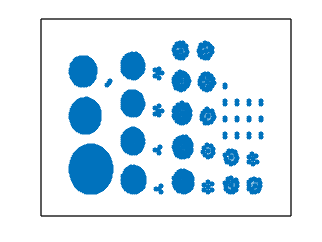


% Crear identificadores únicos para los países
[unique_countries, ~, country_idx] = unique(repArin1.Pais);
num_countries = numel(unique_countries);

% Crear identificadores únicos para los bots (IPs en este caso)
% Asumiendo que cada IP es única y representa un bot
unique_bots = (1:height(repArin1))' + num_countries; % Desplazar los IDs de bot después de los IDs de país

% Crear las aristas, conectando cada bot con su país correspondiente
edges = [country_idx, unique_bots];

% Convertir los códigos de país a un vector de celdas o strings para etiquetas
country_labels = string(unique_countries); % Si es necesario usar string(unique_countries);

% Crear los nombres de los nodos
nodeNames = [cellstr(unique_countries); cellstr(repArin1.IP)]; % Asegúrate de que son strings

% Crear el objeto del grafo y dibujarlo
G = graph(edges(:,1), edges(:,2));
figure;
p = plot(G, 'Layout', 'force');


% Generar una paleta de colores, uno para cada país
colorMap = jet(num_countries); % 'jet' es una función que crea una paleta de colores

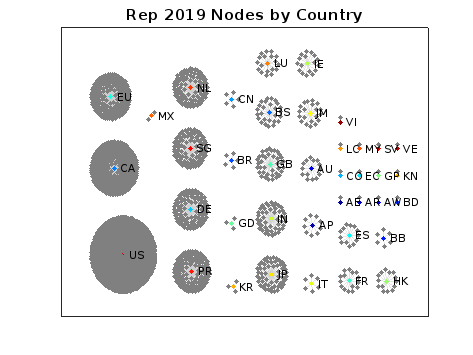


% Aplicar el color a los nodos de país basándose en el índice de país
% Los nodos de país van de 1 a num_countries, los bots siguen después
nodeColors = repmat([0.5 0.5 0.5], num_countries + height(repArin1), 1); % Gris para bots
nodeColors(1:num_countries, :) = colorMap; % Colores de 'jet' para países

% Aplicar colores personalizados a los nodos
p.NodeColor = nodeColors;

% Establecer el tamaño de los marcadores
p.MarkerSize = 7;

% Etiquetar solo los nodos de país para evitar un gráfico sobrecargado
labelnode(p, 1:num_countries, country_labels); 

% Ajustar los límites de los ejes si es necesario
axis tight;

% Título del gráfico
title('Rep 2019 Nodes by Country');
% Personalizar el gráfico con colores y tamaños

p.MarkerSize = 3;
p.EdgeColor = [0.8 0.8 0.8];

% Título del gráfico
title('Rep 2019 Nodes by Country');
% Asegúrese de que el gráfico sea visible
set(gcf, 'Visible', 'on');

### 1.2. REPUTATION 2013

Repetimos el proceso anterior para las IP de Reputation 2013.

repu13=leerRepu('reputation2013.csv')

repu13 = 258626x9 table
           IP           Fiabilidad    Riesgo     MaliciousHost        Pais          Ciudad       Latitud    Longitud    X 
    ________________    __________    ______    _______________    ___________    ___________    _______    ________    __

    "222.76.212.189"        4           2       "Scanning Host"    CN             Xiamen          24.48      118.08     11
    "222.76.212.185"        4           2       "Scanning Host"    CN             Xiamen          24.48      118.08     11
    "222.76.212.186"        4           2       "Scanning Host"    CN             Xiamen          24.48      118.08     11
    "5.34.246.67"           6           3       "Spamm

ip=arrayfun(@ip2bin,repu13.IP);
ip=arrayfun(@bin2dec,ip);
sol13=false(1, length(ip));
for i=1:length(ip)
    sol13(i)=esta(ip(i),limites);
end
sol13

Obtenemos las distintas IPs, con su país, región y tipo de ataque.

repArin2= table(repu13.IP(sol13));
repArin2 = renamevars(repArin2, 'Var1', 'IP');
repArin2.Pais = repu13.Pais(sol13);
repArin2.MaliciousHost = repu13.MaliciousHost(sol13)

repArin2 = 56605x3 table
           IP               Pais         MaliciousHost 
    _________________    ___________    _______________

    "66.2.49.232"        US             "Scanning Host"
    "174.142.46.19"      <undefined>    "Spamming"     
    "66.2.49.244"        US             "Scanning Host"
    "24.218.26.112"      US             "Scanning Host"
    "184.154.37.226"     US             "Spamming"     
    "192.157.254.179"    US             "Spamming"     
    "198.50.194.49"      CA             "Spamming"     
    "108.61.71.18"       US             "Malware IP"   
    "66.2.49.196"        US             "Scanning Host"
    "66.2.49.195"        US             "Scanning Host"
    "66.2.49.194"        US             "Scanning Host"
    "66.2.49.243"        US             "Scanning Host"
    "66.2.49.230"        US             "Scanning Host"
    "24.218.26.117"      US     

Como vemos existen un número bastante mayor de IP de Reputation correspondientes a 2013 que coinciden con las de Arin sobre las de 2019. Esto puede deberse a que en 2013 se tienen en cuenta muchos más tipos de ataques a diferencia de 2019, donde solo se tienen IP de tipo 'Malicious Host'.

Por lo que realizaremos una selección, para únicamente tomar las IPs de 'Malicious Host.'

indice = strcmp(repArin2.MaliciousHost, 'Malicious Host');
repArin3 = repArin2(indice, :)

repArin3 = 652x3 table
           IP               Pais         MaliciousHost  
    _________________    ___________    ________________

    "208.202.62.19"      US             "Malicious Host"
    "199.83.95.136"      US             "Malicious Host"
    "96.228.69.3"        US             "Malicious Host"
    "66.193.171.227"     US             "Malicious Host"
    "71.83.173.33"       US             "Malicious Host"
    "74.117.61.66"       US             "Malicious Host"
    "192.157.200.61"     US             "Malicious Host"
    "199.180.116.133"    US             "Malicious Host"
    "23.81.180.90"       <undefined>    "Malicious Host"
    "64.186.61.18"       US             "Malicious Host"
    "67.18.118.226"      US             "Malicious Host"
    "72.47.251.134"      US             "Malicious Host"
    "192.198.94.98"      US             "Malicious Host"
    "209.42.77.17" 

Representamos gráficamente.

repArin4 = table(repArin3.IP);
repArin4 = renamevars(repArin4, 'Var1', 'IP');
repArin4.Pais = repArin3.Pais

repArin4 = 652x2 table
           IP               Pais    
    _________________    ___________

    "208.202.62.19"      US         
    "199.83.95.136"      US         
    "96.228.69.3"        US         
    "66.193.171.227"     US         
    "71.83.173.33"       US         
    "74.117.61.66"       US         
    "192.157.200.61"     US         
    "199.180.116.133"    US         
    "23.81.180.90"       <undefined>
    "64.186.61.18"       US         
    "67.18.118.226"      US         
    "72.47.251.134"      US         
    "192.198.94.98"      US         
    "209.42.77.17"       US         
    "50.79.80.49"        US         
    "50.192.199.22"      US         



%Seleccionamos aquellos que tienen un país definido.
repArin4(any(ismissing(repArin4), 2),:) = []

repArin4 = 627x2 table
           IP            Pais
    _________________    ____

    "208.202.62.19"       US 
    "199.83.95.136"       US 
    "96.228.69.3"         US 
    "66.193.171.227"      US 
    "71.83.173.33"        US 
    "74.117.61.66"        US 
    "192.157.200.61"      US 
    "199.180.116.133"     US 
    "64.186.61.18"        US 
    "67.18.118.226"       US 
    "72.47.251.134"       US 
    "192.198.94.98"       US 
    "209.42.77.17"        US 
    "50.79.80.49"         US 
    "50.192.199.22"       US 
    "68.166.246.195"      US 



% Crear identificadores únicos para los países
[unique_countries, ~, country_idx] = unique(repArin4.Pais);
num_countries = numel(unique_countries);

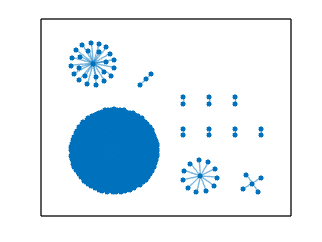


% Crear identificadores únicos para los bots (IPs en este caso)
% Asumiendo que cada IP es única y representa un bot
unique_bots = (1:height(repArin4))' + num_countries; % Desplazar los IDs de bot después de los IDs de país

% Crear las aristas, conectando cada bot con su país correspondiente
edges = [country_idx, unique_bots];

% Convertir los códigos de país a un vector de celdas o strings para etiquetas
country_labels = string(unique_countries); % Si es necesario usar string(unique_countries);

% Crear los nombres de los nodos
nodeNames = [cellstr(unique_countries); cellstr(repArin4.IP)]; % Asegúrate de que son strings

% Crear el objeto del grafo y dibujarlo
G = graph(edges(:,1), edges(:,2));
figure;
p = plot(G, 'Layout', 'force');


% Generar una paleta de colores, uno para cada país
colorMap = jet(num_countries); % 'jet' es una función que crea una paleta de colores

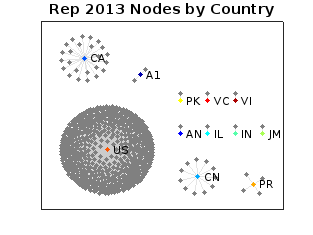


% Aplicar el color a los nodos de país basándose en el índice de país
% Los nodos de país van de 1 a num_countries, los bots siguen después
nodeColors = repmat([0.5 0.5 0.5], num_countries + height(repArin4), 1); % Gris para bots
nodeColors(1:num_countries, :) = colorMap; % Colores de 'jet' para países

% Aplicar colores personalizados a los nodos
p.NodeColor = nodeColors;

% Establecer el tamaño de los marcadores
p.MarkerSize = 7;

% Etiquetar solo los nodos de país para evitar un gráfico sobrecargado
labelnode(p, 1:num_countries, country_labels); 

% Ajustar los límites de los ejes si es necesario
axis tight;

% Título del gráfico
title('Rep 2013 Nodes by Country');
% Personalizar el gráfico con colores y tamaños

p.MarkerSize = 3;
p.EdgeColor = [0.8 0.8 0.8];

% Título del gráfico
title('Rep 2013 Nodes by Country');
% Asegúrese de que el gráfico sea visible
set(gcf, 'Visible', 'on');

Como podemos observar tenemos muchas menos IPs de tipo 'Malicious Host' correspondientes a las IPs de 2013 en comparación con las IPs de 2019 respectivas a la zona de Arin. Para entender los posibles motivos de este hecho, sabemos que cuando una IP está asociada a un 'Malicious Host implica que dicha dirección se identifica como parte de una infraestructura utilizada para llevar a cabo actividades maliciosas en Internet, como ataques informáticos o fraudes en línea. 

Por lo que un crecimiento exponencial como el que vemos, en un período de 6 años, pasamos de tener *apenas* 652 IPs a 7643 IPs en la zona Arin, asociadas a tipo Malicous Host, es decir asociadas a actividades maliciosas en Internet; puede deberse a factores como: un incremento de la ciberdelincuencia, uso más extendido de tecnologías vulnerables (IoT) lo que hace que los dispositivos y servicios tengan deficiencias de seguridad que los hacen vulnerables a ser utilizados como 'Malicious Hosts' o incluso la facilidad de adquisición de IPs donde es más fácil adquirir IPs anónimas para actores malicioses 

Por otro lado como vemos, tanto en el grafo de las Reputation de 2013, como en el de las de 2019, existen IPs correspondientes a Arin que pertenecen a otros países que no están en esta zona de Estados Unidos, Canada o partes del Caribe, hecho que podría deberse a un rediccionamiento de las IPs. Además, vemos que esta distribución de direcciones aumenta con el tiempo, lo que podría ser causa del crecimiento constante de Internet y el incremento de dispositivos conectados, la demanda de direcciones IP continúa creciendo en todo el mundo. Esto puede llevar a que las organizaciones busquen direcciones IP disponibles en otras regiones.

### 1.3. ZEROACCESS

Este estudio se hace con la finalidad de entender cómo afectó el virus zeroaccess en 2019 este virus en la mayor parte de Europa y Rusia.

Antes que nada, añadimos un poco de información sobre este virus:

**Orígenes y Descubrimiento**

ZeroAccess fue descubierto por primera vez en 2011 y rápidamente se destacó por su diseño complejo y su capacidad de infiltrarse en los sistemas Windows sin ser detectado por los antivirus convencionales. Se estima que el malware infectó a millones de ordenadores en todo el mundo.

**¿Qué es un Rootkit?**

Para entender mejor ZeroAccess, es esencial conocer qué es un rootkit. Un rootkit es un tipo de malware que proporciona a los atacantes acceso administrativo no autorizado a un ordenador. Una vez instalado, el rootkit oculta su presencia y la de otros programas maliciosos, lo que dificulta su detección y eliminación. ZeroAccess es considerado uno de los rootkits más avanzados debido a sus técnicas de ocultamiento.

**Métodos de Infección**

ZeroAccess se propaga de varias maneras, incluyendo:

- Descargas Maliciosas: A través de sitios web comprometidos que instalan el malware sin el conocimiento del usuario.

- Archivos Adjuntos de Correo Electrónico: Utilizando correos electrónicos de phishing que engañan a los usuarios para que descarguen y ejecuten el archivo adjunto malicioso.

- Redes P2P (Peer-to-Peer): Aprovechando redes de intercambio de archivos para distribuir el malware.

- Exploits en Navegadores: Utilizando vulnerabilidades en navegadores web y plugins para ejecutar código malicioso.

**Funcionamiento del Virus ZeroAccess**

Una vez que ZeroAccess infecta un sistema, realiza varias acciones para asegurar su persistencia y ocultamiento:

- Modificación del Sistema de Archivos: ZeroAccess se instala en el sistema operativo modificando archivos críticos y utilizando técnicas de rootkit para esconderse. Esto incluye la modificación del registro de Windows y la creación de archivos ocultos.

- Conexión a una Botnet: Los sistemas infectados se convierten en parte de una botnet, una red de ordenadores controlados remotamente por los atacantes. Esta botnet puede ser utilizada para diversos fines maliciosos.

- Técnicas de Evasión: ZeroAccess emplea múltiples técnicas para evitar ser detectado por el software antivirus, como la inyección de código en procesos legítimos, el uso de firmas digitales falsificadas y la modificación de controladores del sistema.

**Objetivos del Virus**

El principal objetivo de ZeroAccess es generar ganancias para los atacantes a través de varias actividades ilícitas:

- Minado de Criptomonedas: Uno de los usos más comunes de ZeroAccess es el minado de criptomonedas. El malware utiliza los recursos del sistema infectado para minar monedas como Bitcoin, generando ingresos para los atacantes.

- Fraude de Clics en Publicidad: ZeroAccess puede generar clics falsos en anuncios en línea, lo que se traduce en ingresos por publicidad para los atacantes a expensas de los anunciantes legítimos.

- Robo de Datos: Aunque no es el enfoque principal de ZeroAccess, también puede ser utilizado para robar información sensible del sistema infectado.

- Distribución de Otros Malware: ZeroAccess puede servir como una plataforma para descargar e instalar otros tipos de malware en el sistema infectado, como troyanos bancarios o ransomware.

**Impacto y Consecuencias**

ZeroAccess ha tenido un impacto significativo en la seguridad informática y la economía digital:

- Recursos del Sistema: El minado de criptomonedas y otras actividades de ZeroAccess consumen considerablemente los recursos del sistema, ralentizando el rendimiento del ordenador infectado.

- Costos Económicos: Las actividades fraudulentas, como el fraude de clics, generan pérdidas significativas para los anunciantes y las plataformas de publicidad.

- Riesgos de Seguridad: La presencia de ZeroAccess en un sistema puede abrir puertas a otros tipos de ataques y comprometer la seguridad de la información.

**Detección y Eliminación**

Debido a sus sofisticadas técnicas de ocultamiento, ZeroAccess es difícil de detectar y eliminar. Algunas de las estrategias para abordar este malware incluyen:

- Software Antivirus: Utilizar programas antivirus actualizados que puedan detectar y eliminar rootkits. Algunos antivirus han desarrollado herramientas específicas para combatir ZeroAccess.

- Análisis Forense: En algunos casos, puede ser necesario realizar un análisis forense del sistema para identificar y eliminar completamente el rootkit.

- Reinstalación del Sistema Operativo: En infecciones graves, la solución más efectiva puede ser la reinstalación completa del sistema operativo.

**Colaboración Internacional**

La lucha contra ZeroAccess ha involucrado la colaboración internacional entre empresas de ciberseguridad, gobiernos y fuerzas del orden. En varias ocasiones, se han realizado operaciones para desmantelar partes de la botnet de ZeroAccess, aunque su naturaleza descentralizada y resiliente ha dificultado su eliminación total.

#### **Análisis Geográfico del Impacto del Virus ZeroAccess**

Ahora que se sabe toda la información sobre este virus, y las graves consecuencias que se pueden tener en caso de que se infecte nuestro ordenador, se puede proceder a analizar cómo se distribuyó este virus a lo largo de la zona de EEUU y Canada. Cabe destacar que el la información del virus zeroaccess viene definida en el .mat de Zeus. Para representar el mapa se empleará la función *mapazeus.m*.

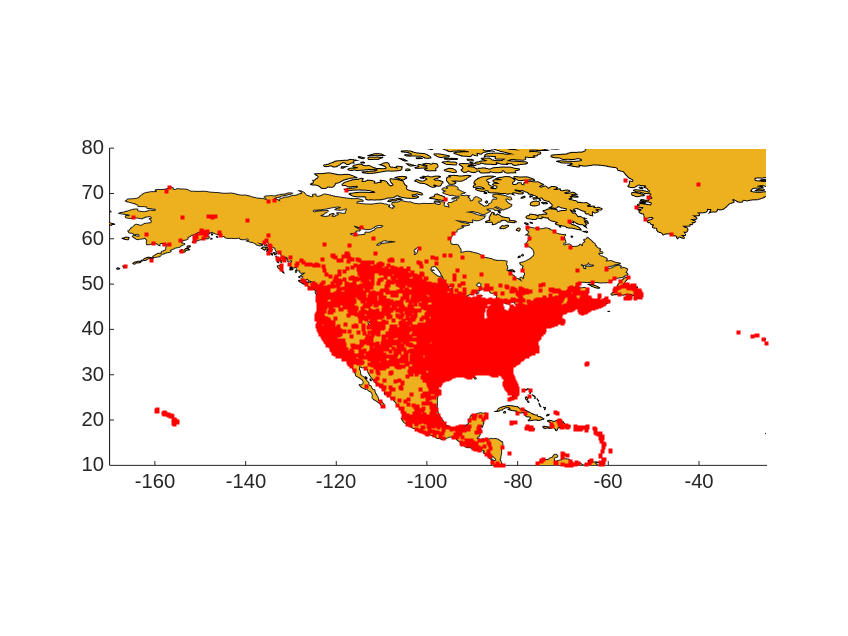

load Zeus.mat
geoshow('landareas.shp')
mapazeus(zeroaccess,'r') %función que para cada lat y long del fichero zeroacces las representa en un mapamundi.
%limites para visualizar la zona de ARIN.
xlim([-170 -25])
ylim([10 80])

Las principales conclusiones de este apartado son:

- EE.UU. fue claramente el epicentro de la propagación de ZeroAccess en esta región, con una enorme concentración en áreas urbanas y tecnológicamente avanzadas.

- Factores como el uso masivo de ordenadores personales, la conectividad constante a internet y las redes domésticas sin protección suficiente facilitaron la propagación.

- La extensión hacia México y partes del sur de Canadá sugiere que el malware aprovechó conexiones transfronterizas y vectores de infección comunes, como descargas fraudulentas, cracks de software, y vulnerabilidades no parcheadas.

- Este patrón confirma la capacidad del virus ZeroAccess para explotar redes globales y distribuirse rápidamente en zonas con alta conectividad, afectando millones de dispositivos sin necesidad de intervención física.

### **Implicaciones y Consecuencias**

**Impacto Económico**

La alta densidad de infecciones en Estados Unidos y el sur de Canadá ha tenido consecuencias económicas importantes. ZeroAccess estaba diseñado principalmente para actividades delictivas como el fraude de clics publicitarios y el minado no autorizado de criptomonedas, lo que generó pérdidas tanto para usuarios individuales como para grandes corporaciones.

Empresas de publicidad digital perdieron ingresos por tráfico falso, mientras que usuarios particulares y empresas vieron disminuido el rendimiento de sus equipos, un mayor consumo eléctrico, y en muchos casos, robos de recursos computacionales. Este tipo de malware también eleva los costes en seguridad informática, mantenimiento y recuperación de sistemas.

**Desafíos en Ciberseguridad**

La propagación masiva del virus en la zona ARIN pone en evidencia vulnerabilidades estructurales en la ciberseguridad doméstica y empresarial.

Aunque Estados Unidos y Canadá tienen una de las infraestructuras tecnológicas más avanzadas del mundo, la cantidad de infecciones demuestra que la tecnología sin políticas de protección adecuadas no es suficiente.

Muchas infecciones se dieron por malas prácticas de seguridad, como el uso de software no actualizado, contraseñas débiles, o la descarga de programas piratas. Esto revela una brecha crítica en la educación digital del usuario promedio, incluso en países altamente conectados.

**Colaboración Internacional**

Dado el papel de EE.UU. como epicentro de las infecciones en la región ARIN, fue necesaria la intervención de agencias como el FBI y el Departamento de Seguridad Nacional, en coordinación con empresas tecnológicas privadas (Microsoft, Symantec, etc.), para interrumpir la infraestructura del botnet.

La experiencia de ARIN muestra que la colaboración entre el sector público, el privado y organizaciones internacionales es esencial para enfrentar amenazas globales como ZeroAccess, que no reconocen fronteras y afectan a redes interconectadas a escala global.

**Evolución del Malware**

El éxito de ZeroAccess en esta región evidencia la capacidad de los cibercriminales para adaptarse a los entornos más protegidos. EE.UU. y Canadá, a pesar de tener recursos avanzados en ciberdefensa, no fueron inmunes.

El virus logró evadir herramientas antivirus, utilizar técnicas sofisticadas de rootkit y actualizarse automáticamente, lo que prolongó su actividad maliciosa durante años.

Esto obliga a replantearse las estrategias de defensa, pasando de una lógica reactiva a una postura proactiva, basada en la inteligencia de amenazas, simulaciones y cibereducación.

## 2. BLOQUES ASN

Se ha scrapeado las IPs que tenemos en los diferentes archivos con consultas a la API  de la página web [https://ipinfo.io](https://ipinfo.io) , se ha descargado los datos de cada IP en formato JSON. 

Se han utilizado métodos de multiprocesos para poder conseguir los datos en el menor tiempo posible.

`import requests`

`import` `json`

`from` `concurrent``.``futures` `import` `ThreadPoolExecutor`

`import` `pandas` `as` `pd`

`import` `sys`

`import` `requests`

`from` `concurrent``.``futures` `import` `ThreadPoolExecutor`

`df` `=` `pd``.``read_csv``(``r``"sda proy\ASN``\R``EPUTATION``\f``iltered_repu_2013.csv"``)`

`# Dividir el DataFrame en dos partes: una con 49k filas y otra con el resto`

`df_49k` `=` `df``.``iloc``[:``49000``]`

`df_restante` `=` `df``.``iloc``[``49000``:]`

`# API Keys`

`API_KEYS` `=`` [``"9***********0"``, ``"d***********f"``]`

`# Función para hacer la solicitud a ipinfo con API Key`

`def` `consulta_ip``(``ip``, ``api_key``):`

    `url` `=` `f``"https://ipinfo.io/``{``ip``}``/json"`

    `headers` `=`` {`

        `"Authorization"``: ``f``"Bearer ``{``api_key``}``"`

`    }`

    `try``:`

        `response` `=` `requests``.``get``(``url``, ``headers``=``headers``, ``timeout``=``10``)`

        `if` `response``.``status_code` `==` `200``:`

            `return` `ip``, ``response``.``json``()`

        `else``:`

            `return` `ip``, {``"error"``: ``f``"Status code ``{``response``.``status_code``}``"``}`

    `except` `Exception` `as` `e``:`

        `return` `ip``, {``"error"``: ``f``"Exception: ``{``str``(``e``)``}``"``}`

`# Función para procesar un DataFrame con una API Key`

`def` `procesar_dataframe``(``df``, ``api_key``, ``output_file``):`

    `resultados` `=`` {}`

    `ips` `=` `df``[``'IP'``].dropna().unique().tolist()`

    `with` `ThreadPoolExecutor``(``max_workers``=``10``) ``as` `executor``:`

        `for` `ip``, ``data` `in` `executor``.``map``(``lambda` `ip``: ``consulta_ip``(``ip``, ``api_key``), ``ips``):`

            `resultados``[``ip``] ``=` `data`

    `with` `open``(``output_file``, ``"w"``) ``as` `f``:`

        `json``.``dump``(``resultados``, ``f``, ``indent``=``4``)`

    `print``(``f``"Datos guardados en ``{``output_file``}``"``)`

`# Procesar el primer DataFrame con la primera API Key`

`procesar_dataframe``(``df_49k``, ``API_KEYS``[``0``], ``"info_ips_repu_2013_p1.json"``)`

`# Procesar el DataFrame restante con la segunda API Key`

`procesar_dataframe``(``df_restante``, ``API_KEYS``[``1``], ``"info_ips_repu_2013_p2.json"``)`

El fichero generado contiene  las columnas siguientes: 

- `ip: ``IP con información `

- `city: ``Ciudad`

- `region: ``Estado o Región`

- `country: ``País`

- `loc: ``Coordenadas`

- `org: ``Organización y ASN de la organizacion/institución a la que se ha asignado la IP`

- `postal: ``Código Postal del lugar de la IP`

- `timezone: ``Zona horaria del lugar de la IP`

- `hostname:`` Nombre del host que dónde está la IP`

`Leemos los archivos generados para reputation 2013, reputation 2019, zeus y delegated.`

% Ruta relativa a la carpeta ASN
asnFolder = fullfile(pwd, 'ASN');  

% Verificar que la carpeta ASN existe
if ~isfolder(asnFolder)
    error('La carpeta ASN no existe en: %s', asnFolder);
end

% Lista de archivos esperados en CSV
filesExpected = {'info_ips_zeus.csv', 'info_ips_combinado_DELEGATED.csv', ...
                 'ips_datos_repu_2013.csv', 'info_ips_repu_2019.csv'};

% Cargar archivos CSV
for i = 1:length(filesExpected)
    filePath = fullfile(asnFolder, filesExpected{i});
    if ~isfile(filePath)
        error('El archivo "%s" no se encontró en la carpeta ASN.', filesExpected{i});
    end

    % Cargar directamente en tabla
    dataTable = readtable(filePath, 'PreserveVariableNames', true);

    % Guardar en workspace con nombre de variable sin ".csv"
    assignin('base', erase(filesExpected{i}, '.csv'), dataTable);
end

disp('Archivos CSV cargados correctamente.');

Archivos CSV cargados correctamente.


### 2.1 ZEUS

Se comenzará a estudiar los ASN del archivo `info_ips_zeus.csv` que contiene información sobre las **direcciones IP asociadas al botnet ZeuS (Zbot)**. Este botnet es conocido por:

- Robar credenciales de **banca online**, **emails** y **redes sociales**.

- Infectar equipos mediante **phishing** o malware.

- Establecer conexiones con **servidores C&C (Command & Control)** para recibir órdenes.

zeus = readtable(fullfile(asnFolder, 'info_ips_zeus.csv'));
coord = split(zeus.loc, ',');
zeus.Lat = str2double(coord(:,1));
zeus.Lon = str2double(coord(:,2));

% Lista de países de la zona ARIN
arin_countries = ["US", "CA", "MX", "BM", "BS", "VG", "AI", "AG", "BB", ...
                  "KY", "DM", "GD", "JM", "KN", "LC", "MS", "PR", "TT", ...
                  "TC", "VC", "VI"];
head(zeus)

          city                 region          country            loc                                    org                              postal           timezone                          hostname                       Lat        Lon  
    _________________    __________________    _______    ____________________    __________________________________________________    __________    __________________    ___________________________________________    ______    _______

    {'Tseung Kwan O'}    {'Sai Kung'      }    {'HK'}     {'22.3279,114.2499'}    {'AS3223 Voxility LLP'                           }    9.9908e+05    {'Asia/Hong_Kong'}    {0×0 char    

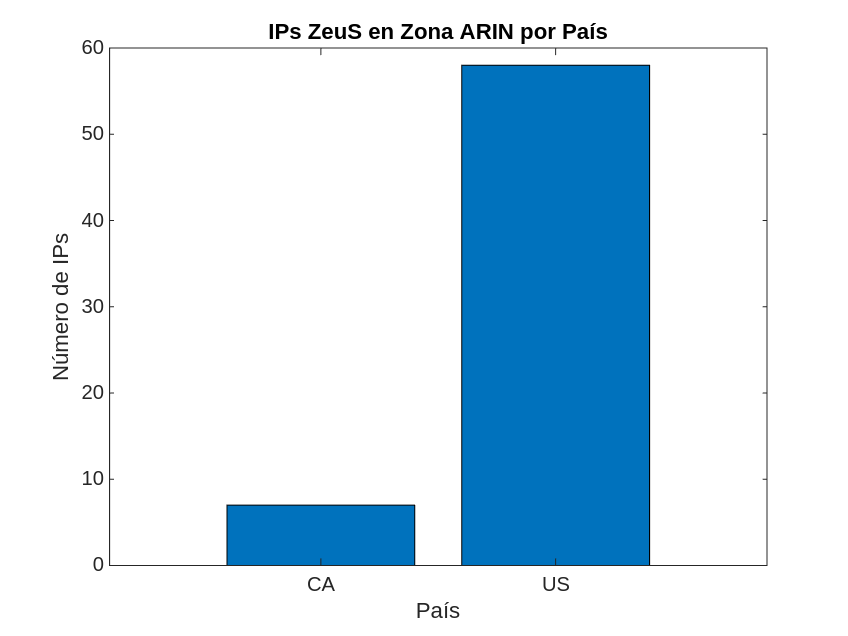


% Filtrar por ARIN
zeus_arin = zeus(ismember(zeus.country, arin_countries), :);

% Contar IPs por país correctamente
top_countries = groupcounts(zeus_arin, 'country');

% Gráfico de barras
figure;
bar(categorical(top_countries.country), top_countries.GroupCount);
title('IPs ZeuS en Zona ARIN por País');
xlabel('País'); ylabel('Número de IPs');

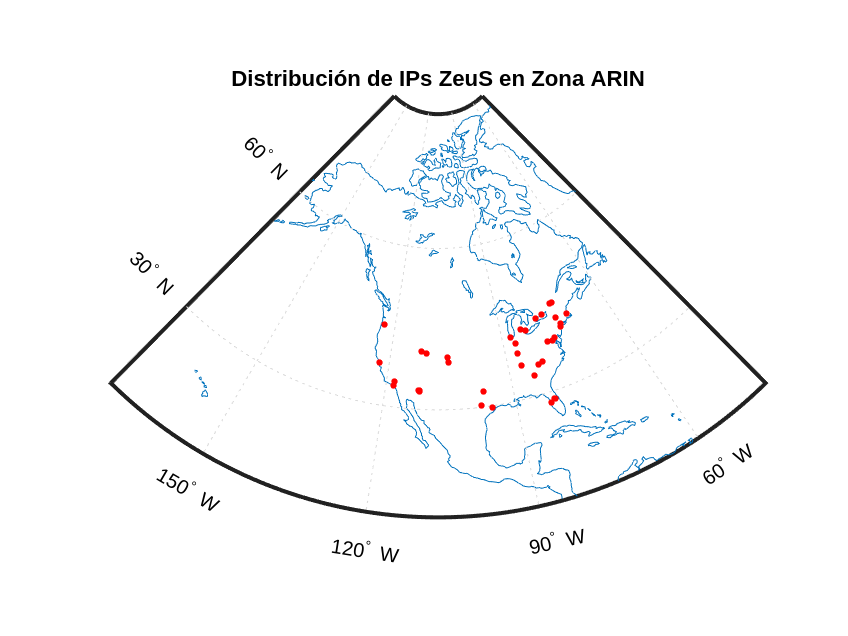

% Mapa de IPs ZeuS en ARIN
figure;
worldmap('North America');
load coastlines
plotm(coastlat, coastlon);
scatterm(zeus_arin.Lat, zeus_arin.Lon, 10, 'r', 'filled');
title('Distribución de IPs ZeuS en Zona ARIN');


% Contar organizaciones en ARIN
top_countries = sortrows(top_countries, 'GroupCount', 'descend');
top_org = groupcounts(zeus_arin, "org")

top_org = 46×3 table
                      org                       GroupCount    Percent
    ________________________________________    __________    _______

    {0×0 char                              }        6         9.2308 
    {'AS11042 NETWORK TRANSIT HOLDINGS LLC'}        2         3.0769 
    {'AS11215 Logix'                       }        1         1.5385 
    {'AS11404 Wave Broadband'              }        1         1.5385 
    {'AS13213 UK-2 Limited'                }        2         3.0769 
    {'AS13468 Kingston Online Services'    }        1         1.5385 
    {'AS14574 RTC Communications'          }        1         1.5385 
    {'AS14992 NewtekOne, Inc.'             }        1         1.5385 
    {'AS16276 OVH SAS'                     }        3         4.6154 
    {'AS16509 Amazon.com, Inc.'            }        1         1.5385 
    {'AS17 Purdue University'       

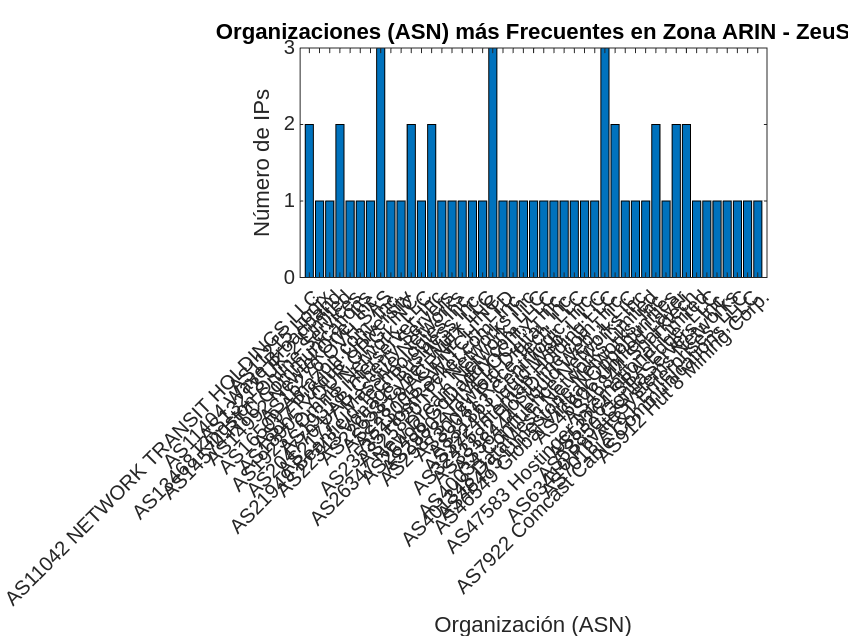


% Gráfico de barras de organizaciones
figure;
bar(categorical(top_org.org), top_org.GroupCount);
title('Organizaciones (ASN) más Frecuentes en Zona ARIN - ZeuS');
xlabel('Organización (ASN)');
ylabel('Número de IPs');
xtickangle(45)

#### **Análisis: IPs afectadas por Zeus:**

**Análisis de Resultados** **Gráfico 1: IPs ZeuS en Zona ARIN por País**

- **Países Detectados:**

- **Estados Unidos (US):** 57 IPs maliciosas.

- **Canadá (CA):** 7 IPs maliciosas.

- **Interpretación:**

- Dominancia absoluta de EE.UU. como ubicación de nodos ZeuS en ARIN.

- La presencia en Canadá es testimonial.

- No hay registros para México ni el Caribe, lo que puede indicar:

- Poca actividad del botnet en esas zonas.

- O que las IPs maliciosas de esas áreas ya fueron desactivadas o no están presentes en el dataset.

**Gráfico 2: Mapa de IPs ZeuS en Zona ARIN**

- **Observaciones:**

- Alta concentración de IPs en la costa este de EE.UU. (Nueva York, Washington D.C., etc.).

- Presencia en zonas industriales de la costa oeste (California).

- Zonas del interior de EE.UU. también presentan focos importantes.

- Poca o nula presencia en México y Caribe (como ya sugería el gráfico anterior).

**Gráfico 3: Organizaciones (ASN) más Frecuentes en ARIN - ZeuS**

- **Observaciones:**

- Gran dispersión de las IPs entre diferentes ASNs, lo que indica que no está centralizado en un pequeño número de proveedores.

- Algunas ASNs destacan ligeramente, pero ninguna concentra más de 3 IPs.

### 2.2 DELEGATED

Realizamos lo mismo con el archivo info_ips_combinado_DELEGATED.csv

delegate_asn = readtable(fullfile(asnFolder, 'info_ips_combinado_DELEGATED.csv'));
head(delegate_asn)

          IP                 city               region          country             loc                                org                        postal           timezone                     hostname              anycast
    _______________    ________________    _________________    _______    _____________________    __________________________________________    ______    _______________________    ___________________________    _______

    {'192.94.72.0'}    {'Farmingville'}    {'New York'     }    {'US'}     {'40.8312,-73.0296' }    {'AS393992 Town of Brookhaven'           }    11738     {'America/New_York'   }    {0×0 char                 }     

% Identificar filas con valores no válidos en la columna loc
invalid_coords = ~contains(delegate_asn.loc, ',');

% Mostrar cuántas filas hay y eliminarlas
num_invalid = sum(invalid_coords);
fprintf('Se han detectado %d filas con coordenadas nulas o no válidas. Se eliminarán.\n', num_invalid);

Se han detectado 134 filas con coordenadas nulas o no válidas. Se eliminarán.



% Eliminar las filas no válidas
delegate_asn(invalid_coords, :) = [];

% Extraer las coordenadas correctamente ahora
coord = split(delegate_asn.loc, ',');
delegate_asn.Lat = str2double(coord(:,1));
delegate_asn.Lon = str2double(coord(:,2));


coord = split(delegate_asn.loc, ',');
delegate_asn.Lat = str2double(coord(:,1));
delegate_asn.Lon = str2double(coord(:,2));

% TOP N países (ajusta el número a tu gusto)
N = 10;

% Agrupar y ordenar
top_countries = groupcounts(delegate_asn, 'country');
top_countries = sortrows(top_countries, 'GroupCount', 'descend');

% Mostrar solo el TOP N
disp('Top países por número de IPs:');

Top países por número de IPs:


disp(top_countries(1:min(N, height(top_countries)), :));

    country    GroupCount    Percent
    _______    __________    _______

    {'US'}       65895        85.119
    {'CA'}        8674        11.205
    {'GB'}         292       0.37719
    {'PR'}         249       0.32164
    {'DE'}         222       0.28677
    {'NL'}         177       0.22864
    {'JP'}         176       0.22735
    {'AU'}         165       0.21314
    {'HK'}         146       0.18859
    {'BR'}         128       0.16534



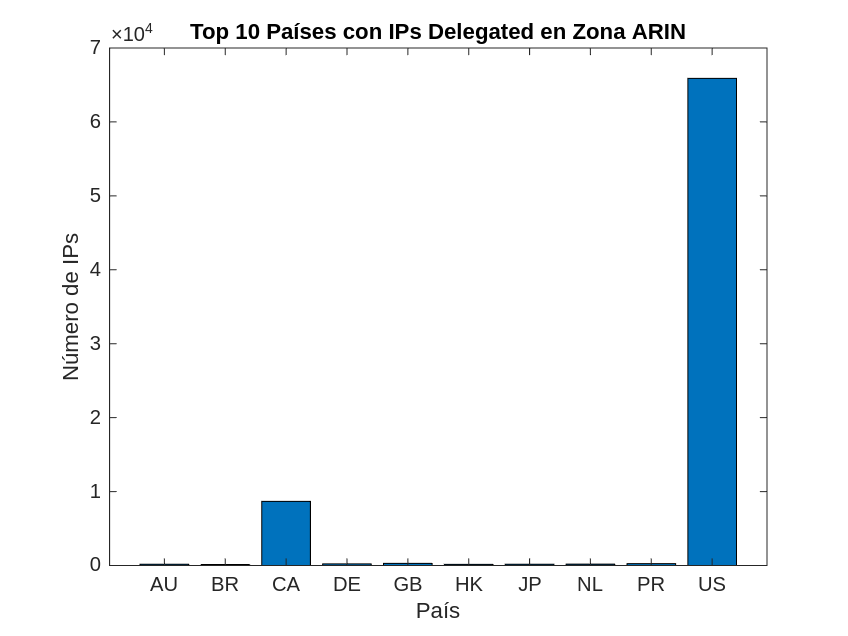

figure;
bar(categorical(top_countries.country(1:N)), top_countries.GroupCount(1:N));
title(sprintf('Top %d Países con IPs Delegated en Zona ARIN', N));
xlabel('País'); ylabel('Número de IPs');

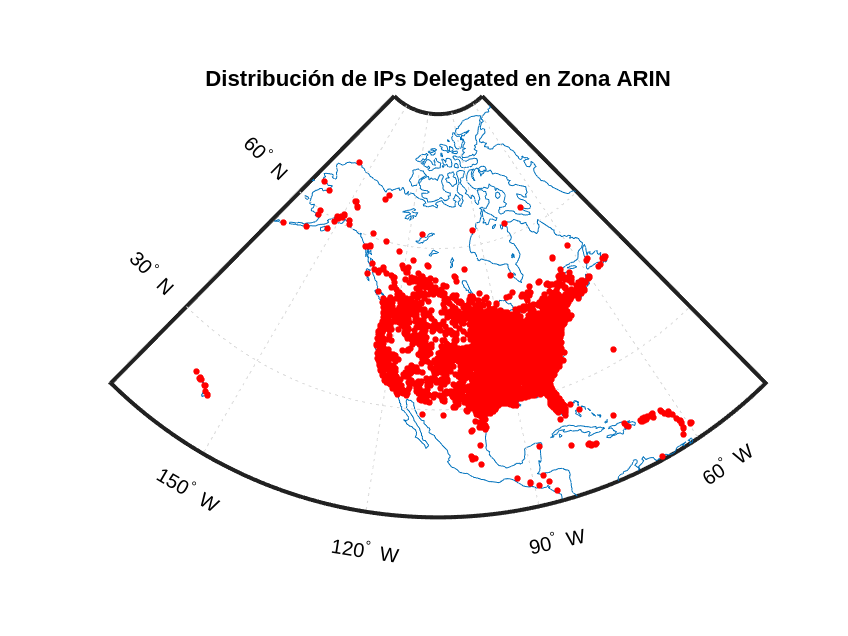

% Mapa de IPs Delegated en ARIN
figure;
worldmap('North America');
load coastlines
plotm(coastlat, coastlon);
scatterm(delegate_asn.Lat, delegate_asn.Lon, 10, 'r', 'filled');
title('Distribución de IPs Delegated en Zona ARIN');

% Análisis de Organizaciones (ASN)
top_orgs = groupcounts(delegate_asn, 'org');
top_orgs = sortrows(top_orgs, 'GroupCount', 'descend')

top_orgs = 13955×3 table
                       org                        GroupCount    Percent
    __________________________________________    __________    _______

    {0×0 char                                }      29370        37.938
    {'AS16509 Amazon.com, Inc.'              }       1791        2.3135
    {'AS749 DoD Network Information Center'  }       1114         1.439
    {'AS7018 AT&T Enterprises, LLC'          }        522       0.67429
    {'AS7029 Windstream Communications LLC'  }        395       0.51024
    {'AS721 DoD Network Information Center'  }        323       0.41723
    {'AS174 Cogent Communications'           }        288       0.37202
    {'AS14618 Amazon.com, Inc.'              }        271       0.35006
    {'AS14265 TPx Communications'            }        250       0.32293
    {'AS3561 CenturyLink Communications, LLC'}        235       0.30356
    {'AS

#### **Análisis Comparativo: IPs Delegated en Zona ARIN **

**Gráfico 1: IPs Delegated en Zona ARIN por País (TOP 10)**

- EEUU domina claramente la presencia de IPs, concentrando más del 85%.

- Canadá ocupa la segunda posición, muy lejos de EEUU, pero con cierta relevancia (11%).

- Aparecen países **fuera de ARIN (GB, DE, NL, JP, AU, HK, BR)**, lo que indica:

- O bien transferencias de rangos IP a través de ARIN.

- O bases de datos con registros incompletos o históricos.

- Puerto Rico (PR), aunque pequeño, tiene una representación esperable.

**Gráfico 2: Mapa de IPs Delegated en ARIN**

- Se confirma la fuerte concentración de IPs en:

- Costa Este y Centro de EE.UU.

- California y costa Oeste.

- Alta dispersión en México y Caribe, a diferencia de lo que se observó en el dataset ZeuS.

- Más densidad de IPs en todo el continente americano, lo que sugiere que el dataset **Delegated** es mucho más amplio y recoge rangos de IPs completos, no solo IPs comprometidas.

**Gráfico 3: Top 10 Organizaciones (ASN)**

- **Amazon (AS16509 y AS14618)** es el actor dominante, con más de 2.000 IPs.

- Proveedores de comunicaciones tradicionales como **AT&T**, **Cogent**, **CenturyLink**, **Comcast** también aparecen en el top.

- Presencia del **DOD (Department of Defense)**, lo que indica que parte de sus rangos de IP están incluidos en las bases de datos públicas o se han registrado movimientos de delegación

### 2.3 REPUTATION 2013 Y 2019

Ahora se procederá a estudiar ambos archivos con la información de las ips de reputation. 

%1. Carga y Limpieza de Datos
asnFolder = fullfile(pwd, 'ASN');
repu2013_asn = ipsdatosrepu2013(fullfile(asnFolder, 'ips_datos_repu_2013.csv'))

repu2013_asn = 53516×8 table
           city              region        country           loc            org     postal         timezone                            hostname                   
    __________________    _____________    _______    _________________    _____    ______    ___________________    _____________________________________________

    1                     2                  3        4                        5        6     7                      "8"                                          
    Västerås              Västmanland        SE       59.6162,16.5528      57858      NaN     Europe/Stockholm       ""                                           
    San Jose              California         U

repu2013_asn(1,:)=[]

repu2013_asn = 53515×8 table
           city              region        country           loc            org     postal         timezone                            hostname                   
    __________________    _____________    _______    _________________    _____    ______    ___________________    _____________________________________________

    Västerås              Västmanland        SE       59.6162,16.5528      57858      NaN     Europe/Stockholm       ""                                           
    San Jose              California         US       37.3394,-121.8950    22530    95025     America/Los_Angeles    "66-2-49-232.hou-01.cvx.algx.net"            
    San Jose              California         U

head(repu2013_asn)

           city              region        country           loc            org     postal         timezone                            hostname                   
    __________________    _____________    _______    _________________    _____    ______    ___________________    _____________________________________________

    Västerås              Västmanland        SE       59.6162,16.5528      57858      NaN     Europe/Stockholm       ""                                           
    San Jose              California         US       37.3394,-121.8950    22530    95025     America/Los_Angeles    "66-2-49-232.hou-01.cvx.algx.net"            
    San Jose              California         US       37.3394,-121.8950    

repu2019_asn = readtable(fullfile(asnFolder, 'info_ips_repu_2019.csv'));
head(repu2019_asn)

                         hostname                               city                region         country             loc                                 org                         postal           timezone            anycast
    __________________________________________________    _________________    ________________    _______    _____________________    ____________________________________________    ______    _______________________    _______

    {'23-94-213-6-host.colocrossing.com'             }    {'Los Angeles'  }    {'California'  }    {'US'}     {'34.0522,-118.2437'}    {'AS36352 HostPapa'                        }    90009     {'America/Los_Angeles'}      NaN  
    {'23-

Nos interesa centrarnos en las ips de la zona ARIN así que hacemos una selección. 

% Lista de países ARIN
arin_countries = ["US", "CA", "MX", "BM", "BS", "VG", "AI", "AG", "BB", ...
                  "KY", "DM", "GD", "JM", "KN", "LC", "MS", "PR", "TT", ...
                  "TC", "VC", "VI"];

   org no está en el mismo formato en 2013 y 2019 , así que para poder compararlos buscamos el código del AS de cada organización de 2013 en 2019 y le asignamos el mismo nombre. 

% Convertir columna country a string
repu2013_asn.country = string(repu2013_asn.country);
repu2019_asn.country = string(repu2019_asn.country);

% Filtrar solo IPs de la zona ARIN
repu2013_arin = repu2013_asn(ismember(repu2013_asn.country, arin_countries), :);
repu2019_arin = repu2019_asn(ismember(repu2019_asn.country, arin_countries), :);

% Paso 1: Extraer ASN y nombre de repu2019_arin
repu2019_arin.org = string(repu2019_arin.org);
filtro_as = startsWith(repu2019_arin.org, "AS");
orgs_2019_filtrados = repu2019_arin.org(filtro_as);

asn_2019 = regexp(orgs_2019_filtrados, '^AS(\d+)', 'tokens', 'once');
asn_2019 = cellfun(@(x) str2double(x), asn_2019);

tabla_asn_nombre = table(asn_2019, orgs_2019_filtrados, ...
                         'VariableNames', ["asn", "org_completo"]);
tabla_asn_nombre = unique(tabla_asn_nombre, 'rows');

% Paso 2: Convertir org de 2013 a ASN y unir con los nombres
repu2013_arin.org = string(repu2013_arin.org);
repu2013_arin.asn = str2double(repu2013_arin.org);

% Join por ASN
repu2013_arin = outerjoin(repu2013_arin, tabla_asn_nombre, ...
                         'LeftKeys', 'asn', ...
                         'RightKeys', 'asn', ...
                         'Type', 'left', ...
                         'MergeKeys', true);

%renombrar para claridad
repu2013_arin.org_estandarizado = repu2013_arin.org_completo;
% Asegúrate de que loc sea string (en ambas tablas)
repu2013_arin.loc = string(repu2013_arin.loc);
repu2019_arin.loc = string(repu2019_arin.loc);

Ahora queremos representar las ips de cada año para ver si hay diferencias geográficas. 

% PASO 1: Preparar coordenadas y limpiar tipo
repu2013_arin.loc = string(repu2013_arin.loc);
repu2019_arin.loc = string(repu2019_arin.loc);

% Separar latitud y longitud
coords_2013 = split(repu2013_arin.loc, ',');
lat_2013 = str2double(coords_2013(:,1));
lon_2013 = str2double(coords_2013(:,2));

coords_2019 = split(repu2019_arin.loc, ',');
lat_2019 = str2double(coords_2019(:,1));
lon_2019 = str2double(coords_2019(:,2));


% Mapa de IPs Delegated en ARIN 2013
% Asegúrate de limpiar figuras anteriores
close all;

% Crear la figura (sin mostrarla si falla la interfaz)
fig = figure('Visible', 'off');  % Cambia a 'on' si tu entorno gráfico ya funciona

% Crear mapa base
worldmap('North America');
load coastlines;
plotm(coastlat, coastlon);

% Ploteo de IPs (lat/lon)
scatterm(lat_2013, lon_2013, 10, 'r', 'filled');

% Título del mapa
title('Distribución de IPs ARIN - Año 2013');

% Guardar como imagen PNG
saveas(fig, 'mapa_ips_arin_2013.png');

% Mensaje de confirmación
disp("Imagen guardada como 'mapa_ips_arin_2013.png' en la carpeta de trabajo.");

Imagen guardada como 'mapa_ips_arin_2013.png' en la carpeta de trabajo.


Hemos guardado la foto y adjuntado porque fallaba la interfaz gráfica. 

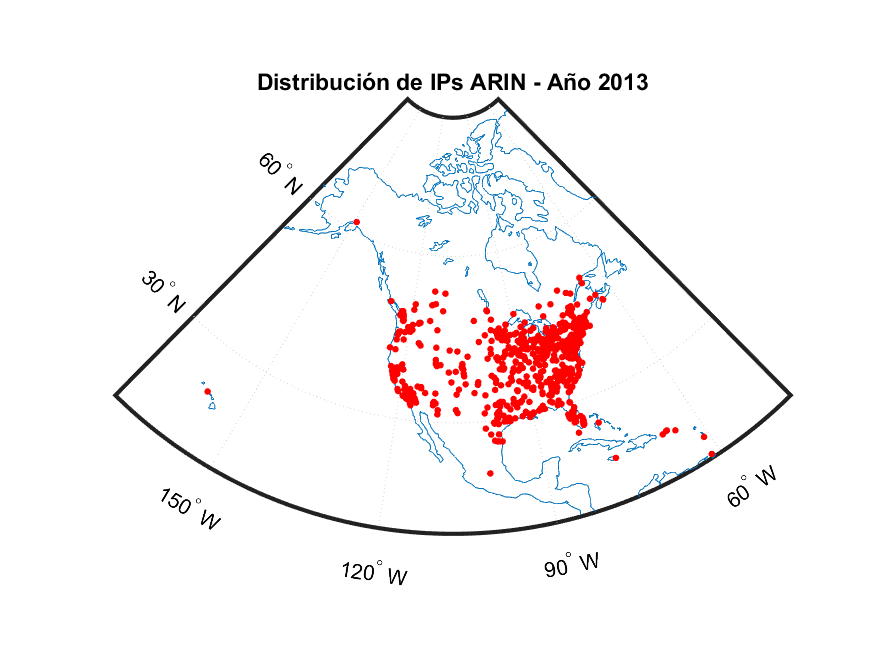

% Mapa de IPs Delegated en ARIN
% Asegúrate de limpiar figuras anteriores
close all;

% Crear la figura (sin mostrarla si falla la interfaz)
fig = figure('Visible', 'off');  % Cambia a 'on' si tu entorno gráfico ya funciona

% Crear mapa base
worldmap('North America');
load coastlines;
plotm(coastlat, coastlon);

% Ploteo de IPs (lat/lon)
scatterm(lat_2019, lon_2019, 10, 'r', 'filled');

% Título del mapa
title('Distribución de IPs ARIN - Año 2019');

% Guardar como imagen PNG
saveas(fig, 'mapa_ips_arin_2019.png');

% Mensaje de confirmación
disp("Imagen guardada como 'mapa_ips_arin_2019.png' en la carpeta de trabajo.");

Imagen guardada como 'mapa_ips_arin_2019.png' en la carpeta de trabajo.


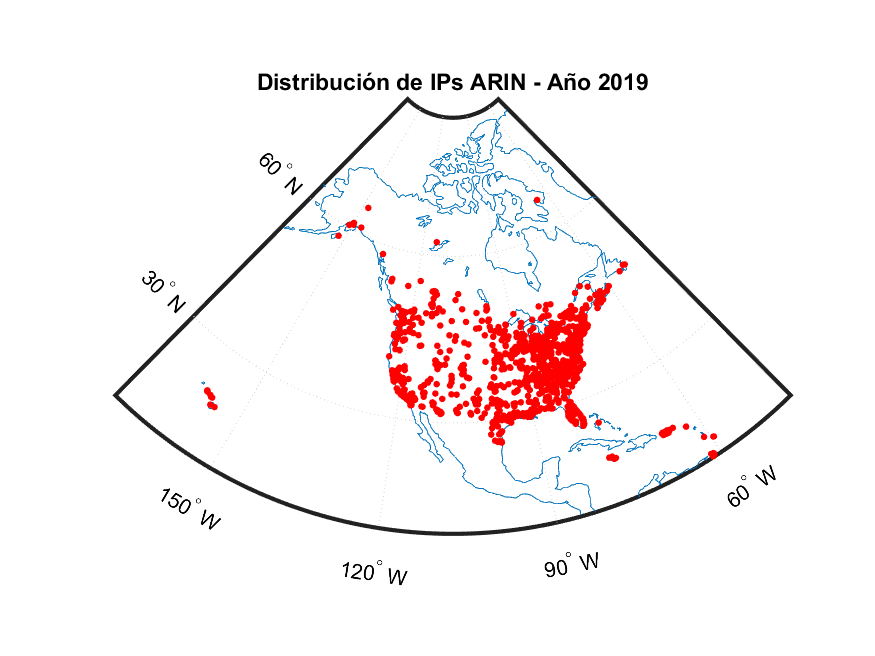

repu2013_arin.country = string(repu2013_arin.country);
repu2019_arin.country = string(repu2019_arin.country);
% Contar países 2013
top_countries_2013 = groupcounts(repu2013_arin, 'country');
top_countries_2013 = sortrows(top_countries_2013, 'GroupCount', 'descend');

% Si tiene menos de 10 filas, tomar todas las que haya
N = min(10, height(top_countries_2013));
top_countries_2013 = top_countries_2013(1:N, :);


% Contar países 2019
top_countries_2019 = groupcounts(repu2019_arin, 'country');
top_countries_2019 = sortrows(top_countries_2019, 'GroupCount', 'descend');
top_countries_2019 = top_countries_2019(1:10, :);

%Crear figura (sin mostrar)
fig = figure('Visible', 'off');
bar(categorical(top_countries_2013.country), top_countries_2013.GroupCount);
xlabel('País');
ylabel('Número de IPs');
title('Top 10 Países con IPs - ARIN 2013');
saveas(fig, 'top_paises_arin_2013.png');
disp("Guardado: top_paises_arin_2013.png");

Guardado: top_paises_arin_2013.png


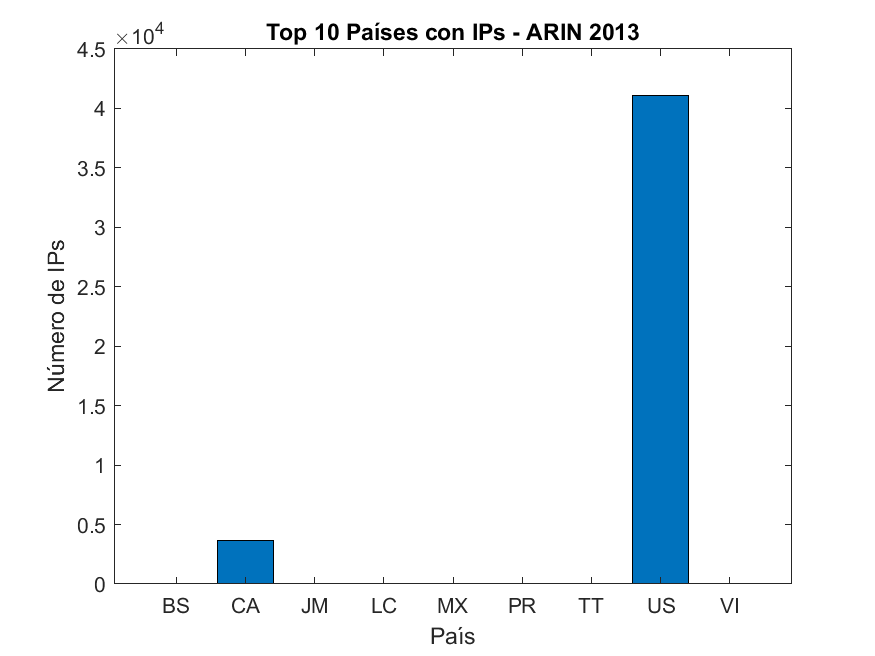

%Crear figura (sin mostrar)
fig = figure('Visible', 'off');
bar(categorical(top_countries_2019.country), top_countries_2019.GroupCount);
xlabel('País');
ylabel('Número de IPs');
title('Top 10 Países con IPs - ARIN 2019');
saveas(fig, 'top_paises_arin_2019.png');
disp("Guardado: top_paises_arin_2019.png");

Guardado: top_paises_arin_2019.png


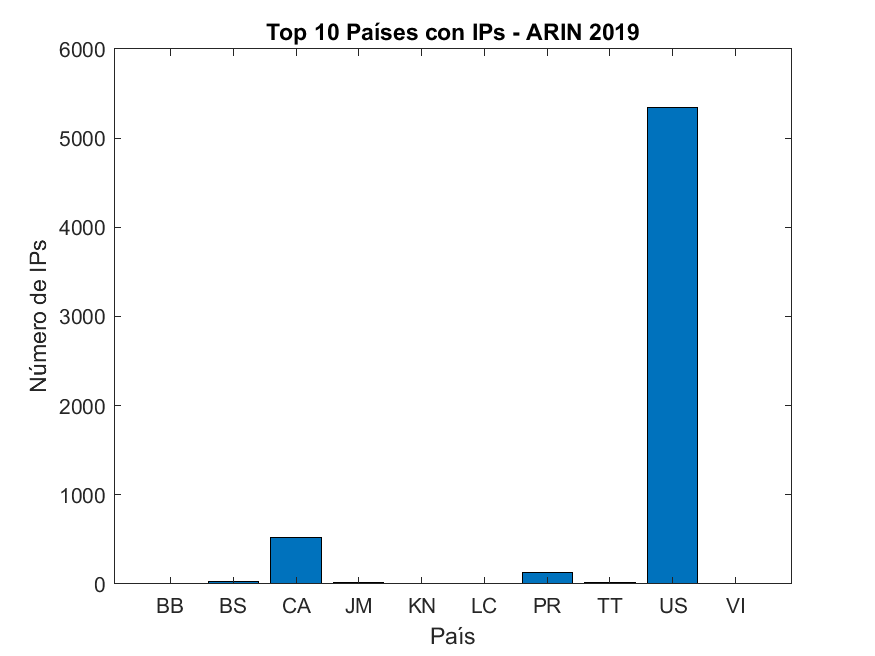

% Asegúrate de que tienes el nombre de la organización
repu2013_arin.org_completo = string(repu2013_arin.org_completo);

% Contar IPs por organización
top_orgs_2013 = groupcounts(repu2013_arin, 'org_completo');
top_orgs_2013 = sortrows(top_orgs_2013, 'GroupCount', 'descend');

% Mostrar top 10
disp("Top 10 organizaciones en 2013:");

Top 10 organizaciones en 2013:


disp(top_orgs_2013(1:10, :));

                   org_completo                   GroupCount    Percent
    __________________________________________    __________    _______

    <missing>                                       11764       26.292 
    "AS16509 Amazon.com, Inc."                       3496       7.8135 
    "AS25820 IT7 Networks Inc"                       2981       6.6625 
    "AS20454 SECURED SERVERS LLC"                    1766        3.947 
    "AS8075 Microsoft Corporation"                   1542       3.4463 
    "AS13768 Aptum Technologies"                     1117       2.4965 
    "AS701 Verizon Business"                         1067       2.3847 
    "AS36351 IBM Cloud"                               950       2.1232 
    "AS7922 Comcast Cable Communications, LLC"        912       2.0383 
    "AS33070 Rackspace Hosting"                       818       1.8282 



% Asegúrate de que tienes el nombre de la organización
repu2019_arin.org = string(repu2019_arin.org);

% Contar IPs por organización
top_orgs_2019 = groupcounts(repu2019_arin, 'org');
top_orgs_2019 = sortrows(top_orgs_2019, 'GroupCount', 'descend');

% Mostrar top 10
disp("Top 10 organizaciones en 2019:");

Top 10 organizaciones en 2019:


disp(top_orgs_2019(1:10, :));

                       org                        GroupCount    Percent
    __________________________________________    __________    _______

    "AS14061 DigitalOcean, LLC"                      721         11.89 
    "AS7922 Comcast Cable Communications, LLC"       643        10.604 
    "AS7018 AT&T Enterprises, LLC"                   294        4.8483 
    "AS237 Merit Network Inc."                       287        4.7328 
    "AS10439 CariNet, Inc."                          277        4.5679 
    "AS701 Verizon Business"                         185        3.0508 
    "AS6939 Hurricane Electric LLC"                  170        2.8034 
    "AS20115 Charter Communications LLC"             147        2.4241 
    "AS6128 Cablevision Systems Corp."               136        2.2427 
    ""                                               112         1.847 



#### **Comparativa de IPs Maliciosas en Zona ARIN – 2013 vs 2019 (Reputation Datasets)**

Gráfico 1: IPs Maliciosas en Zona ARIN por País (TOP 10)

- **EE.UU. domina ampliamente** el número de IPs maliciosas detectadas en ambos años:

- En **2013** representa más del **91%** de todas las direcciones IP incluidas.

- En **2019**, se mantiene como líder con un **88%**, aunque con una reducción absoluta de volumen.

- **Canadá (CA)** conserva el segundo lugar en ambos años, con una participación cercana al **9%**.

- Otros países del entorno ARIN que aparecen en el top son:

- **Puerto Rico (PR)**, **Trinidad y Tobago (TT)**, **México (MX)**, **Islas Vírgenes (VI)**, **Jamaica (JM)** o **Bahamas (BS)**.

- La aparición de países como **San Cristóbal y Nieves (KN)** o **Santa Lucía (LC)** podría deberse a:

- Delegaciones IP técnicas dentro de ARIN.

- Uso de IPs de hosting o servicios VPS desde esos territorios.

La presencia en estas listas no indica que el país sea fuente directa de ataques, sino que **la actividad maliciosa ha sido rastreada a direcciones IP asociadas a infraestructuras dentro de dichos países**, ya sea por abuso, uso fraudulento o falta de control.

**Gráfico 2: Mapa de IPs Maliciosas en ARIN**

- El mapa de **2013** muestra una concentración muy clara en:

- La **costa este de EE.UU.**, el **medio oeste** (Ohio, Illinois, Texas), y la **costa oeste** (California).

- También se detectan focos maliciosos en **México**, el **Caribe** y zonas puntuales de **Canadá**.

- En **2019**, pese a la menor cantidad de IPs, se observa **más dispersión**:

- Aparecen nuevas zonas en **Florida**, **Hawái**, el **oeste de Canadá** y más puntos en **Centroamérica y el Caribe**.

Esta dispersión creciente puede deberse tanto a una **mejora en la geolocalización de IPs** como a una **estrategia de distribución más descentralizada por parte de actores maliciosos**.**Gráfico 3: Top 10 Organizaciones (ASN) 2013**

- **Amazon (AS16509)** destaca con más de **3.400 IPs maliciosas** detectadas.

- Le siguen organizaciones como **IT7 Networks**, **Secured Servers**, **Microsoft (AS8075)**, **Comcast** y **IBM Cloud**.

- Estas IPs maliciosas probablemente provienen de servicios cloud, VPS o infraestructura comprometida usada para:

- Scanning masivo.

- Distribución de malware.

- Actividades de spam, phishing o control de botnets.

**2019**

- El panorama cambia. Encabezan la lista:

- **DigitalOcean**, **Comcast**, **AT&T**, **Merit Network**, **CariNet**, y **Hurricane Electric**.

- **Amazon y Microsoft desaparecen del top**, lo cual sugiere que han adoptado:

- **Controles más estrictos en sus plataformas**.

- **Sistemas de detección de abuso más eficaces**.

- **Políticas de mitigación temprana para contener actividad sospechosa** dentro de sus redes.

Esta evolución podría reflejar una **maduración en las políticas de seguridad de grandes actores cloud**. Al mismo tiempo, **nuevos proveedores más accesibles y descentralizados** como DigitalOcean son ahora más susceptibles de ser utilizados con fines maliciosos.

**Comcast y Verizon** mantienen su presencia en ambos años, lo que apunta a una recurrencia en su uso como origen o intermediarios en comportamientos maliciosos.

### Conclusión Final ASN: Análisis Comparado de IPs en Zona ARIN (Zeus, Delegated y Reputation 2013–2019)

A lo largo del análisis comparativo de los tres conjuntos de datos pertenecientes a la zona ARIN **ZeuS, Delegated y Reputation (años 2013 y 2019)** se han observado **diferencias notables tanto en la distribución geográfica de las direcciones IP como en los actores organizativos (ASN)** que las concentran. Estas diferencias permiten inferir **patrones sobre la evolución de la infraestructura de Internet en América del Norte**, así como sobre la **progresión y descentralización de la actividad maliciosa en la red**.

El conjunto **ZeuS**, centrado en **actividad maliciosa asociada a botnets**, muestra una **concentración muy marcada en Estados Unidos**, tanto en términos de número de IPs como en su localización geográfica. Las IPs maliciosas tienden a estar situadas en **grandes núcleos urbanos e industriales**, con especial densidad en la **costa este, California y el medio oeste** del país. Sin embargo, la **dispersión entre los Sistemas Autónomos (ASN) es considerable**, lo que sugiere que la infraestructura utilizada por el malware ZeuS **explota múltiples redes**, muchas veces a través de **servicios comprometidos o proveedores menos vigilantes**.

En cambio, el conjunto **Delegated**, que representa **asignaciones legítimas de IPs**, ofrece una imagen **más estructurada de la infraestructura oficial de red**. **Estados Unidos sigue concentrando la mayoría absoluta de las IPs**, seguido de **Canadá y otros países del entorno ARIN**. Aquí destacan claramente **organizaciones como Amazon, Microsoft, AT&T, Comcast y el Departamento de Defensa de EE.UU.**, lo que evidencia el **papel dominante de estas entidades en la gestión de bloques IP** a gran escala. El mapa refleja una infraestructura **intensamente desarrollada en toda América del Norte**, con cierta expansión hacia el Caribe y Centroamérica.

En el conjunto **Reputation** se observan **dinámicas muy interesantes al comparar los años 2013 y 2019**. En 2013, la cantidad total de IPs maliciosas detectadas fue **muy superior (más de 44.000 frente a solo 6.000 en 2019)**, con una **fuerte concentración en EE.UU. (91%)**, pero también con representación significativa en **Canadá, Puerto Rico, México y otras islas del Caribe**. En 2019, pese al menor volumen, se observa **una mayor dispersión espacial** y la **aparición de nuevas regiones afectadas**. Esto puede interpretarse como una **mejora en los sistemas de detección y geolocalización**, pero también como **una estrategia más descentralizada y evasiva por parte de actores maliciosos**.

Un aspecto particularmente revelador es **la evolución de las organizaciones implicadas en la actividad maliciosa**. En 2013, destacan actores como **Amazon, Microsoft, IBM Cloud y varios proveedores de hosting**, que **concentraban miles de IPs comprometidas**. Esto podría explicarse por una **menor supervisión de sus servicios cloud en ese momento** o por **una explotación masiva por parte de terceros**. Sin embargo, en 2019, **Amazon y Microsoft desaparecen del top de IPs maliciosas**, lo cual sugiere que han **mejorado sustancialmente sus políticas de seguridad**, implantando **sistemas de detección de abusos más eficaces y mecanismos de contención más rápidos**. En su lugar, aparecen organizaciones como **DigitalOcean, Hurricane Electric o CariNet**, lo que podría indicar **un desplazamiento hacia proveedores con menor control o mayor accesibilidad para usuarios malintencionados**.

En conjunto, este análisis revela **una transformación clara en el ecosistema de las IPs maliciosas en la zona ARIN**. Si bien **Estados Unidos sigue siendo el epicentro** tanto de infraestructura como de incidentes, el panorama muestra **signos de maduración por parte de los grandes actores cloud** y, al mismo tiempo, **una fragmentación creciente en los actores secundarios**. La evolución temporal de los datos permite entrever que los **atacantes están adaptando sus tácticas**, **diversificando sus puntos de entrada** y desplazando su actividad hacia **plataformas menos reguladas o menos vigiladas**. Esta tendencia subraya la **importancia de mantener estrategias de ciberseguridad proactivas y colaborativas**, tanto desde el sector público como desde los grandes proveedores de servicios en la nube.

# 3.ESTUDIO DE CORTAFUEGOS

Análizamos la efectividad de un cortafuegos con dos ficheros de datos reales capturados en mayo de 2019 en la UPV; uno antes del cortafuegos y otro después.

pre=leerPre("prefw.txt")
pre=pre(1:end-1, :);

post=leerPost("postfw.txt")

Analizaremos solamente las IPs de Reputation de 2019 y Zeus, puesto que los datos del cortafuegos son de este año y no tendría sentido analizar para las de 2013.

Vamos a seleccionar en primer lugar las IP de ambos fichero que correspondan a Arin con los mismos pasos que hemos seguido para los fucheros de Reputation anteriormente. 

También utilizaremos los límites definidos en la primera parte del proyecto.

pre.IP=arrayfun(@cellstr,pre.IP);
ippre=arrayfun(@ip2bin,pre.IP);
ippre=arrayfun(@bin2dec,ippre);
sol1=false(1,length(ippre));
for i=1:length(ippre);

pre = 136816x1 table
          IP      
    ______________

    13.107.136.9  
    17.253.55.205 
    90.164.107.104
    172.217.16.227
    189.194.86.244
    81.34.28.114  
    31.13.83.52   
    81.22.45.242  
    81.22.45.206  
    81.22.45.210  
    81.35.0.135   
    8.253.96.121  
    104.244.42.65 
    92.118.37.74  
    88.12.237.154 
    92.118.37.74  


    sol1(1,i)=esta(ippre(i),limites);
end
ippre1=ippre(sol1)

post = 150290x1 table
          IP       
    _______________

    212.142.91.105 
    84.232.151.46  
    90.164.107.104 
    192.229.220.133
    90.170.205.101 
    81.90.96.26    
    205.251.192.149
    90.164.107.104 
    212.142.91.105 
    13.107.136.9   
    141.226.218.97 
    205.251.192.149
    90.164.107.104 
    90.170.205.101 
    188.35.21.63   
    8.253.96.121   


pre1=pre(sol1,:)

post.IP=arrayfun(@cellstr,post.IP);
ippost=arrayfun(@ip2bin,post.IP);
ippost=arrayfun(@bin2dec,ippost);
sol2=false(1,length(ippost));
for i=1:length(ippost);
    sol2(1,i)=esta(ippost(i),limites);
end
ippost1=ippost(sol2)
post1=post(sol2,:)

pre1 = 40124x1 table
            IP         
    ___________________

    {'13.107.136.9'   }
    {'17.253.55.205'  }
    {'172.217.16.227' }
    {'8.253.96.121'   }
    {'104.244.42.65'  }
    {'216.58.211.33'  }
    {'216.58.211.33'  }
    {'13.107.136.9'   }
    {'172.217.168.174'}
    {'172.217.16.227' }
    {'23.1.106.237'   }
    {'13.107.136.9'   }
    {'52.58.146.129'  }
    {'54.192.63.231'  }
    {'104.20.66.187'  }
    {'17.253.55.205'  }


### 3.1 REPUTATION 2019

Como ya tenemos etiquetadas las direcciones de los ficheros de reputación vemos cuantas aparecen en el subconjunto de datos obtenido del punto anterior. 

ipsArin=dec2bin(ipArin,32);
ipsArin=cellstr(ipsArin);
ipsArin=arrayfun(@ipbin2dec,ipsArin);
inpre=ismember(ipsArin,pre1.IP);
inpost=ismember(ipsArin,post1.IP);
tabulate(inpre)
tabulate(inpost)

Podemos observar en la tabla que tenemos tan solo un 1.2% de nuestras IP de Arin coincidentes con las direcciones que iban a pasar por el *firewall*. Número que se reduce a un 0% una vez han pasado por el *firewall*, lo que es indicador de que el cortafuegos funciona correctamente.

### 3.2 ZEUS

Como ya tenemos etiquetada las direcciones del fichero de Zeus vemos cuantas aparecen en el subconjunto de datos obtenido del punto anterior.  

ipszArin=dec2bin(ipzArin,32);
ipszArin=cellstr(ipszArin);

post1 = 61737x1 table
            IP         
    ___________________

    {'192.229.220.133'}
    {'205.251.192.149'}
    {'13.107.136.9'   }
    {'205.251.192.149'}
    {'8.253.96.121'   }
    {'104.244.42.65'  }
    {'54.192.63.231'  }
    {'54.192.63.231'  }
    {'54.192.63.231'  }
    {'54.192.63.231'  }
    {'54.192.63.231'  }
    {'54.192.63.231'  }
    {'54.192.63.231'  }
    {'54.192.63.231'  }
    {'35.186.224.53'  }
    {'173.194.139.138'}


ipszArin=arrayfun(@ipbin2dec,ipszArin);
inprez=ismember(ipszArin,pre1.IP);
inpostz=ismember(ipszArin,post1.IP);
tabulate(inprez)
tabulate(inpostz)

En este caso, no podemos saber como funciona el cortafuegos, puesto que no hay direcciones IP de Zeus que vayan a pasar por el cortafuegos.

# 4. WIRESHARK

Estudiamos si hay alguna dirección IP que sea usada para ataques de fuerza bruta. Es imprescindible entender que en un contexto de ciberseguridad, estos ataques son una técnica utilizada por los ciberdelincuentes para intentar obtener acceso no autorizado a sistemas informáticos o cuentas mediante la prueba repetida y sistemática de todas las posibles combinaciones de contraseñas u otras credenciales de acceso.

wire = leerWire("fuerzaBruta.csv")
tabulate(wire.Source)
tabulate(wire.Destination)

Como podemos observar existe un gran número de IPs que se repiten un número muy amplio de veces tanto si son de origen o destinación, lo que concuerda con lo que significa que sean ataques de fuerza bruta, con repetición de IP cada vez que se intenta acceder a un sistema informático.

%limpiamos las IPs de origen (carácteres especiales)

  Value    Count   Percent
      0     7551     98.80%
      1       92      1.20%


filas= ~contains(string(wire.Source), ':');

  Value    Count   Percent
      0     7643    100.00%


tabla=wire(filas,:);
ip_bin=arrayfun(@ip2bin, string(tabla.Source));
ip_dec=arrayfun(@bin2dec, ip_bin);


[inf, sup]=arrayfun(@rango, string(arin4.IP), string(arin4.as_number));
limites=[inf, sup];
sols=false(1, length(ip_dec));
for i=1:length(ip_dec)
    sols(i)=esta(ip_dec(i), limites);
end

  Value    Count   Percent
      0       64    100.00%


ips_binD=arrayfun(@ip2bin, string(tabla.Destination));

  Value    Count   Percent
      0       64    100.00%


ips_decD=arrayfun(@bin2dec, ips_binD);

wire = 135146x6 table
             Time                  Source         Destination      Protocol    Length                                              Info                                          
    _______________________    ______________    ______________    ________    ______    ________________________________________________________________________________________

    2019-08-20 07:03:06.541    104.74.213.186    192.168.0.24       TCP          826     [TCP segment of a reassembled PDU]                                                      
    2019-08-20 07:03:06.542    104.74.213.186    192.168.0.24       TCP         1514     [TCP segment of a reassembled PDU]                                                      
    2019-08-20 07:03:06.542    104.74.213.186    192.168.0.24

[inf, sup]=arrayfun(@rango, string(arin4.IP), string(arin4.as_number));

                      Value    Count   Percent
                    0.0.0.0        2      0.00%
            104.134.212.186        1      0.00%
             104.202.95.153        1      0.00%
             104.74.201.251        1      0.00%
             104.74.213.105        1      0.00%
             104.74.213.118        1      0.00%
             104.74.213.130        3      0.00%
             104.74.213.186    61799     45.73%
              104.74.213.66        1      0.00%
              104.74.213.78        1      0.00%
             104.74.229.189        1      0.00%
              104.74.85.153        1      0.00%
              106.14.51.107       20      0.01%
               106.15.15.14        5      0.00%
               110.93.137.9      388      0.29%
             114.95.102.114        1      0.00%
             117.111.24.219       56      0.04%
             124.69.138.177        1      0.00%
               13.107.136.9       31      0.02%
               13.107.6.171        9     

limites=[inf, sup];

                  Value    Count   Percent
      04:32:5c:57:3d:b1        1      0.00%
            10.174.0.13        1      0.00%
         10.209.214.168       42      0.03%
         104.74.213.186     9984      7.39%
         105.74.213.186        1      0.00%
          106.14.51.107       22      0.02%
           106.15.15.14        6      0.00%
              11.0.8.22        1      0.00%
         110.48.101.243        1      0.00%
           110.61.135.9        1      0.00%
           110.93.137.9      232      0.17%
          110.93.45.187        1      0.00%
         117.111.24.219       75      0.06%
        117.152.127.193        1      0.00%
        119.206.198.198        1      0.00%
            12.169.0.24        1      0.00%
        127.227.168.128        2      0.00%
        129.157.250.246        1      0.00%
           129.171.0.24        1      0.00%
           13.107.136.9       31      0.02%
           13.107.6.171       11      0.01%
          13.125.144.73        2 

solD=false(1, length(ips_decD));
for i=1:length(ips_decD)
    solD(i)=esta(ips_decD(i), limites);
end
solD

numel (unique(tabla.Source(sols)))
numel (unique (tabla.Destination(solD)))

Con esto podemos ver que en nuestra región de Arin, hay mayor número de direcciones 'atacantes' que 'atacadas'.

# 5. DE LOS MAPAS A LA REGRESIÓN

Analizamos con mayor profundidad la distribución de las infecciones del zeroaccess, malware conocido por su capacidad para eludir la detección y resistir los intentos de eliminación.

### 5.1 MAPAS DE ZEROACCESS

Seleccionamos las zonas que corresponden a la región de Arin. Nos basamos en la maxima y minima logitud y latitud del archivo cow, para obtener un rango con el que clasificamos cada IP de zeroacces en nuestras dos zonas: USA y Canada.

load geopaises.mat cow
row3=cow.ISO3166A2=="US";
usa = cow(row3, :)

row4 = cow.ISO3166A2=="CA";
canada = cow(row4, :)

load Zeus.mat
rowZilati=zeroaccess(:,1)>=usa.minlatitude;
rowZslati=zeroaccess(:,1)<=usa.maxlatitude;
rowZilong=zeroaccess(:,2)>=usa.minlongitude;
rowZslong=zeroaccess(:,2)<=usa.maxlongitude;
rowZ=and(and(and(rowZilati, rowZslati), rowZilong), rowZslong);
ZeroUSA=zeroaccess(rowZ, :);
worldmap('United States');
geoshow('landareas.shp');
geoshow(ZeroUSA(:,1), ZeroUSA(:,2), 'DisplayType', 'point', 'Marker', '.', 'Color', 'red')

load Zeus.mat
rowZilatiC=zeroaccess(:,1)>=canada.minlatitude;
rowZslatiC=zeroaccess(:,1)<=canada.maxlatitude;
rowZilongC=zeroaccess(:,2)>=canada.minlongitude;
rowZslongC=zeroaccess(:,2)<=canada.maxlongitude;
rowZC=and(and(and(rowZilatiC, rowZslatiC), rowZilongC), rowZslongC);
ZeroCanada=zeroaccess(rowZC, :);
worldmap('Canada');
geoshow('landareas.shp');
geoshow(ZeroCanada(:,1), ZeroCanada(:,2), 'DisplayType', 'point', 'Marker', '.', 'Color', 'red')

tablapuntoszeroaccess = table('Size', [0, 2], ...
                    'VariableTypes', {'string', 'int32'}, ...
                    'VariableNames', {'Pais', 'Puntos'});

usa = 1×71 table
    ISO3166A2    ISO3166A3    ISO3166N3    FIPS104        ISOen_name           ISOen_proper         ISOen_ro_name        ISOen_ro_proper        ISOfr_name        ISOfr_proper                ISOes_name                          UNGEGNen_name                       UNGEGNen_longname                      UNGEGNfr_name                     UNGEGNfr_longname                       UNGEGNes_name                         UNGEGNes_longname                              UNGEGNru_name                                    UNGEGNru_longname                         UNGEGNlc_ro_name                 UNGEGNlc_ro_longname                

datos_canada = table("CA", height(ZeroCanada), 'VariableNames', {'Pais', 'Puntos'});
datos_us = table("US", height(ZeroUSA), 'VariableNames', {'Pais', 'Puntos'});
tablapuntoszeroaccess = [tablapuntoszeroaccess; datos_canada];

canada = 1×71 table
    ISO3166A2    ISO3166A3    ISO3166N3    FIPS104    ISOen_name     ISOen_proper    ISOen_ro_name    ISOen_ro_proper    ISOfr_name     ISOfr_proper     ISOes_name     UNGEGNen_name    UNGEGNen_longname     UNGEGNfr_name      UNGEGNfr_longname     UNGEGNes_name      UNGEGNes_longname     UNGEGNru_name      UNGEGNru_longname           UNGEGNlc_ro_name                UNGEGNlc_ro_longname          BGN_name      BGN_proper     BGN_longname    BGNlc_longname    BGNlc_name      PCGN_name     PCGN_proper  

tablapuntoszeroaccess = [tablapuntoszeroaccess; datos_us];
tablapuntoszeroaccess

Como podemos observar existen una mayoría de puntos (infeccciones) en Estados Unidos en comparación a Canadá.

### 5.2 MAPAS DE REPUTATION

Utilizamos las propias variables de logitud y latitud, así como país de la propia base de datos.

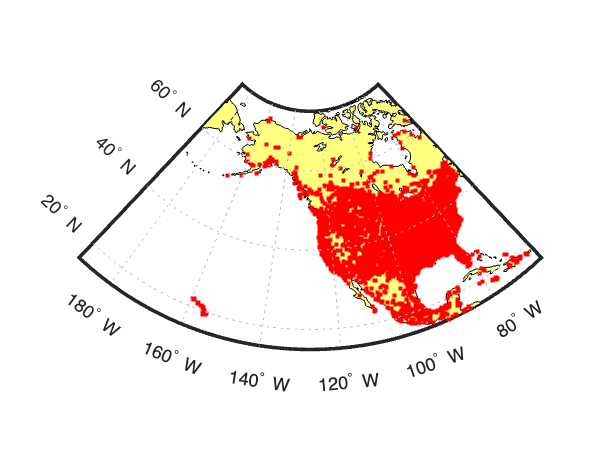

load geopaises.mat
load Zeus.mat
repu_us = repu.Pais == 'US';
repu_ca = repu.Pais == 'CA';
repu_US = repu(repu_us, :);
latiRepu = repu_US(:,7);
longRepu = repu_US(:,8);
worldmap('United States');
geoshow('landareas.shp');

latiRepu = table2array(latiRepu(:, 'Latitud'));
longRepu = table2array(longRepu(:, 'Longitud'));
geoshow(latiRepu, longRepu, 'DisplayType', 'point', 'Marker', '.', 'Color', 'red')

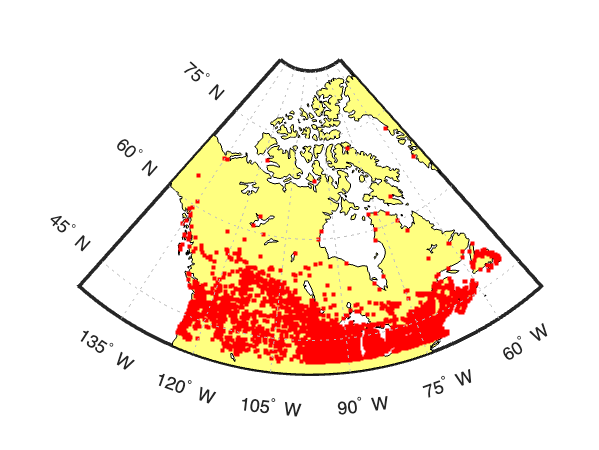

repu_CA = repu(repu_ca, :);
latiRepu = repu_CA(:,7);
longRepu = repu_CA(:,8);
worldmap('Canada');
geoshow('landareas.shp');
latiRepu = table2array(latiRepu(:, 'Latitud'));
longRepu = table2array(longRepu(:, 'Longitud'));
geoshow(latiRepu, longRepu, 'DisplayType', 'point', 'Marker', '.', 'Color', 'red')

tablapuntosrepu = table('Size', [0, 2], ...
                    'VariableTypes', {'string', 'int32'}, ...
                    'VariableNames', {'Pais', 'Puntos'});
datos_canada = table("CA", height(repu_CA), 'VariableNames', {'Pais', 'Puntos'});
datos_us = table("US", height(repu_US), 'VariableNames', {'Pais', 'Puntos'});
tablapuntosrepu = [tablapuntosrepu; datos_canada];
tablapuntosrepu = [tablapuntosrepu; datos_us];
tablapuntosrepu

tablapuntoszeroaccess = 2×2 table
    Pais    Puntos
    ____    ______

    "CA"     91132
    "US"    329775


Como vemos ocurre lo mismo que con los datos de zeroacces, existe un mayor número de infecciones dentro de Estados Unidos que en Canada.

### 5.3 MAPAS DE ARIN

En este caso no podemos realizar mapas porque no tenemos la latitud en longitud de las IPs.

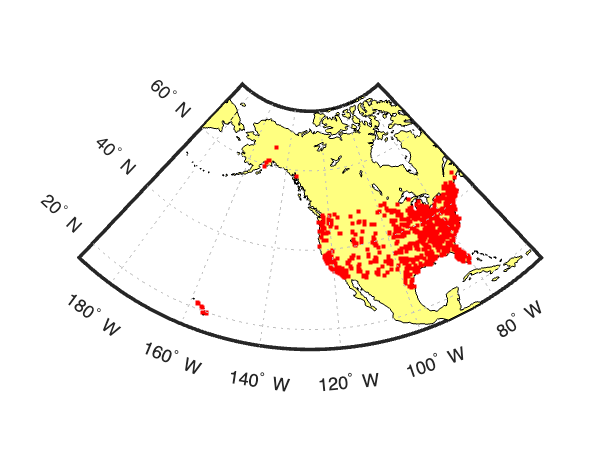

arin_us = arin.pais == 'US';
arin_ca = arin.pais == 'CA';
arin_US = arin(arin_us, :);
arin_CA = arin(arin_ca, :);
tablapuntosarin = table('Size', [0, 2], ...
                    'VariableTypes', {'string', 'int32'}, ...
                    'VariableNames', {'Pais', 'Puntos'});
datos_canada = table("CA", height(arin_CA), 'VariableNames', {'Pais', 'Puntos'});
datos_us = table("US", height(arin_US), 'VariableNames', {'Pais', 'Puntos'});
tablapuntosarin = [tablapuntosarin; datos_canada];
tablapuntosarin = [tablapuntosarin; datos_us];
tablapuntosarin

Pobemos observar de nuevo, como existe un mayor número de IPs que corresponden a Estados Unidos sobre Canada.

### 5.4 CHOROPLETH

El choropleth es un tipo de visualización de datos en la que se representan áreas geográficas, como países, estados, provincias, etc., coloreadas o sombreadas según el valor de una variable específica en cada área. 

Creamos una función, crear_choropleth, con la que con dos tablas; una, de puntos con los países de la zona ARIN compuesta por dos columnas creada por nosotros (nombre del país en formato** ISO2**, **cantidad de puntos; IP **de cada país), y otra, "TM_WORLD_BORDERS-0.3.shp" (Nworld). Se concantenan dichas tablas para encontrar los países ARIN de la tabla Nworld, para de esta froma obtener una nueva tabla con el area, poligono, Bounding box, puntos de cada una de las IPs de cada zona respectivamente... Y con esto, se grafica el choropleth.

Nworld=shaperead("TM_WORLD_BORDERS-0.3.shp");
crear_choropleth(Nworld, tablapuntoszeroaccess)
crear_choropleth(Nworld, tablapuntosrepu)
crear_choropleth(Nworld, tablapuntosarin)

Comprobamos que por los colores, en general Estados Unidos presenta mayor cantidad de IPs en todos los aspectos de las distintas bases.

#### 5.4.1 COMPROBACIÓN

Vamos a comprobar que las IPs de Reputation que en teoría son de la zona Arin se encuentran dentro de los límites de dicha zona. Por un lado comprobamos para Estados Unidos y por otro para Canadá.

comprobacion_ubis(Nworld, repu, tablapuntosrepu,'US')
comprobacion_ubis(Nworld, repu, tablapuntosrepu,'CA')

Podemos observar que solo hay una IP de reputation que no se encuentra dentro de la región respectiva a la que en teoría debería encontrarse (solo una fuera de la Bounding Box). Mientras que para Canada no hay ninguna IP que esté fuera de los límites de su región. Lo que puede deberse a la precisión de los datos geográficos.

#### 5.4.2 MÁS INFORMACIÓN

Obtenemos datos que nos dan más información sobre estas infecciones del ZeroAccess, cuánta gente infectada, como proporción de gente infectada o infecciones por cada mil personas.

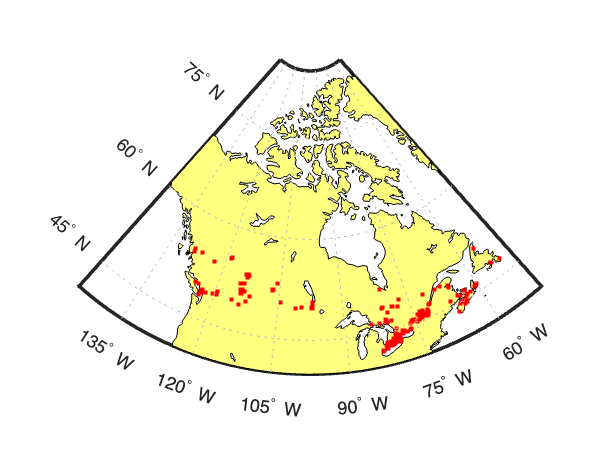

t_count = get_count_table(["CA","US"], zeroaccess, cow)
cow = cow(cow.ISO3166A2=="CA" | cow.ISO3166A2=="US",:)

%nº de personas x infeccion
canada=cow.population(1)/t_count.Points(1)
us=cow.population(2)/t_count.Points(2)
%proporcion de gente infectada
prop_canada=(t_count.Points(1)*100)/cow.population(1)
prop_us=(t_count.Points(2)*100)/cow.population(2)
%infectados cada 1000 personas
inf_canada=(t_count.Points(1)*1000)/cow.population(1)
inf_us=(t_count.Points(2)*1000)/cow.population(2)

tablapuntosrepu = 2×2 table
    Pais    Puntos
    ____    ______

    "CA"      516 
    "US"     6326 


### 5.5 CONCLUSIONES

En general podemos ver una mayor densidad de puntos (infecciones) dentro de Estados Unidos en comparación a Canada. A su vez, vemos que existe una mayor cantidad de IPs de zeros acces que practicamente infectan toda la zona de Arin, dejando muy pocas regiones sin tocar. 

No podemos decir lo mismo para las IPs de Reputation, pues como observamos en el mapa (tablas de puntos), no hay un número tan grande en comparación con ZeroAccess para cubrir toda la zona de Estados Unidos y Canada, no obstante, podemos mencionar que extiste una mayor concentración de puntos en la zona este de USA. Este hecho podría deberse a que la costa este que incluye áreas metropolitanas como Nueva York, Boston, Washington D.C., y Miami, tiene una densidad de población mucho mayor que otras partes del país; y dado que las direcciones IP están asociadas con ubicaciones físicas, es probable que sea la causa de que haya una mayor concentración de direcciones IP en áreas densamente pobladas.

Con los últimos datos, podemos decir que sobre 367.37 personas fueron infectadas con el virus de ZeroAccess en Canada, un número menor a lass 951.70 personas que fueron infectadas en EEUU. Sin embargo también vemos, que si se tiene en cuenta la proporción de personas, un 0.10% de la población de Estados Unidos infectada, y un 0.26% en Canada. Siendo 1.05 infectados para cada 1000 personas en Estados Unidos y 2.64 para cada 1000 personas en Canada. Por ende podemos decir que aunque el número absoluto de casos en Canada es menor, la situación relativa de la infección en términos de la población es más grave en Canada que en Estados Unidos.

# 6. REFINANDO

Vamos a realizar un estudio sobre los estados de USA, de forma que profundizaremos en esta región.

### 6.1 OBTENCIÓN DE INFORMACIÓN DE LOS ESTADOS

ejem=fileread('state_boundaries.json');
data=jsondecode(ejem);
%coordenadas=struct2table(data)
colnames = {'ISO3166A2','nombre','minlatitude','maxlatitude','minlongitude','maxlongitude'};
t_estados = table(cell(0,1), cell(0,1),zeros(0,1), zeros(0,1), zeros(0,1), zeros(0,1), 'VariableNames', colnames);
stateCodes = {'AL', 'AK', 'AZ', 'AR', 'CA', 'CO', 'CT', 'DE', 'FL', 'GA','HI', 'ID', 'IL', 'IN', 'IA', 'KS', 'KY', 'LA', 'ME', 'MD', 'MA', 'MI', 'MN', 'MS', 'MO', 'MT', 'NE', 'NV', 'NH', 'NJ', 'NM', 'NY', 'NC', 'ND', 'OH', 'OK', 'OR', 'PA', 'RI', 'SC', 'SD', 'TN', 'TX', 'UT', 'VT', 'VA', 'WA', 'WV', 'WI', 'WY'};
for i=1:length(stateCodes)
    nom=stateCodes{i};
    newrow={nom,data.(nom).name,data.(nom).min_lat,data.(nom).max_lat,data.(nom).min_lng,data.(nom).max_lng};
    t_estados=[t_estados;newrow];
end


tablapuntosarin = 2×2 table
    Pais    Puntos
    ____    ______

    "CA"    10671 
    "US"    87032 


t_estados.ISO3166A2=string(t_estados.ISO3166A2)

Nworld = 246×1 struct array with fields:
    Geometry
    BoundingBox
    X
    Y
    FIPS
    ISO2
    ISO3
    UN
    NAME
    AREA
    POP2005
    REGION
    SUBREGION
    LON
    LAT


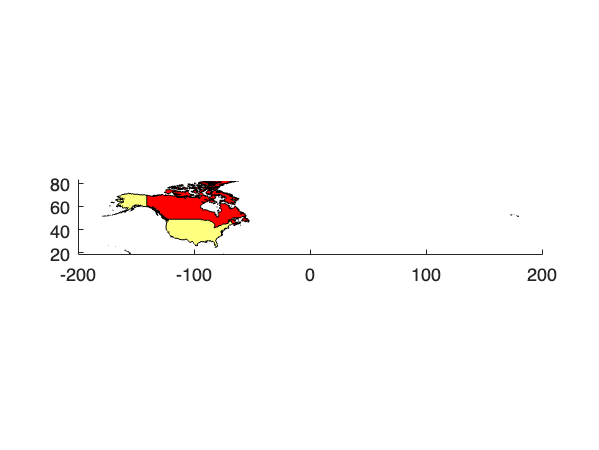

estados=["AL", "AK", "AZ", "AR", "CA", "CO", "CT", "DE", "FL", "GA","HI", "ID", "IL", "IN", "IA", "KS", "KY", "LA", "ME", "MD", "MA", "MI", "MN", "MS", "MO", "MT", "NE", "NV", "NH", "NJ", "NM", "NY", "NC", "ND", "OH", "OK", "OR", "PA", "RI", "SC", "SD", "TN", "TX", "UT", "VT", "VA", "WA", "WV", "WI", "WY"];

t_count2 = get_count_table(estados, zeroaccess, t_estados);

poblacion_estados = leerPob("pobEst.txt");

poblacion_estados.ISO2=strrep(poblacion_estados.ISO2, ':', '');
pob_est = join(poblacion_estados, t_count2, 'Keys', 'ISO2');

for i=1:height(pob_est)
    pob_est.PropInf(i)=(pob_est.Points(i)*100)/pob_est.Pob(i);
end

Número de coordenadas dentro de la bounding box: 6325
Hay 1 IP que no se encuentran dentro de la bounding box


datoschoro=join(pob_est,t_estados,'LeftKeys','ISO2','RightKeys','ISO3166A2')

Número de coordenadas dentro de la bounding box: 516
Todas las IP de reputation de esta zona se encuentran dentro de la bounding box


datoschoro.nombre = string(datoschoro.nombre);
states = readgeotable("usastatelo.shp");
s = innerjoin(states,datoschoro,"LeftKey","Name","RightKey","nombre");

### 6.2 MAPAS POR ESTADOS

figure

t_count = 2×2 table
    ISO2      Points  
    ____    __________

    "CA"         91132
    "US"    3.2978e+05


rows = s.Name ~= "Hawaii" & s.Name ~= "Alaska";

cow = 2×71 table
    ISO3166A2    ISO3166A3    ISO3166N3    FIPS104        ISOen_name           ISOen_proper         ISOen_ro_name        ISOen_ro_proper        ISOfr_name        ISOfr_proper                ISOes_name                          UNGEGNen_name                       UNGEGNen_longname                      UNGEGNfr_name                     UNGEGNfr_longname                       UNGEGNes_name                         UNGEGNes_longname                              UNGEGNru_name                                    UNGEGNru_longname                          UNGEGNlc_ro_name                  UNGEGNlc_ro_longname                

statess = s(rows,:);
geoplot(statess,ColorVariable="Points");

canada = 376.3780

us = 951.7018

geobasemap darkwater
title("Choropleth estados USA Infectados")

prop_canada = 0.2657

cb = colorbar;

prop_us = 0.1051

cb.Label.String = "Infectados";


inf_canada = 2.6569

cmap = flip(summer);

inf_us = 1.0507

colormap(cmap)

geolimits([20.0 55.0],[-128.0 -65.5])

figure
rows = s.Name ~= "Hawaii" & s.Name ~= "Alaska";
statess = s(rows,:);
geoplot(statess,ColorVariable="Pob");

geobasemap darkwater
title("Choropleth estados USA Población")
cb = colorbar;
cb.Label.String = "Infectados";

cmap = flip(summer);
colormap(cmap)

geolimits([20.0 55.0],[-128.0 -65.5])

t_estados = 50×6 table
    ISO3166A2        nombre         minlatitude    maxlatitude    minlongitude    maxlongitude
    _________    _______________    ___________    ___________    ____________    ____________

      "AL"       {'Alabama'    }      30.146         35.004         -88.474         -84.893   
      "AK"       {'Alaska'     }      52.596         71.523         -169.91         -129.99   
      "AZ"       {'Arizona'    }      31.332             37         -114.81         -109.05   
      "AR"       {'Arkansas'   }      33.008           36.5          -94.62         -89.659   
      "CA"       {'California' }      32.512         42.013         -124.65         -114.13   
      "CO"       {'Colorado'   }      36.995         41.001         -109.05         -102.04   
      "CT"  

Como podemos ver en ambos mapas vemos que donde hay más población hay mayor número de infectados. Siendo estos dos estados los que se salen del comportamiento del resto de estados, los anómalos en el siguiente Box & Whiskers.

boxplot(t_count2.Points)

Hemos estudiado el índice correspondiente de cada uno de estos Estados (5,32) respectivo de California y New York.

### 6.3 POR PROPORCIÓN

Estudiamos la proporción de infectados en los distintos estados respecto a su población.

figure
rows = s.Name ~= "Hawaii" & s.Name ~= "Alaska";
statess = s(rows,:);
geoplot(statess,ColorVariable="PropInf");

geobasemap darkwater
title("Choropleth estados USA")
cb = colorbar;
cb.Label.String = "Proporción respecto a la problación";

datoschoro = 50×9 table
    ISO2       Pob        Points    PropInf         nombre         minlatitude    maxlatitude    minlongitude    maxlongitude
    ____    __________    ______    ________    _______________    ___________    ___________    ____________    ____________

    "AL"    4.9032e+06     6626      0.13514    {'Alabama'    }      30.146         35.004         -88.474         -84.893   
    "AK"    7.3154e+05      568     0.077644    {'Alaska'     }      52.596         71.523         -169.91         -129.99   
    "AZ"    7.2787e+06     5962      0.08191    {'Arizona'    }      31.332             37         -114.81         -109.05   
    "AR"    3.0178e+06     4260      0.


cmap = flip(summer);
colormap(cmap)

geolimits([20.0 55.0],[-128.0 -65.5])

Podemos ver que la concentración de infecciones varía de los distintos gráficos. Siendo también, dos estados los que presentan valores anormalmente altos respecto al resto, tal y como vemos en el siguiente Box & Whiskers.

boxplot(pob_est.PropInf)

Siendo estos valores anómalos West Virginia y Kansas (índice 48, 16).

### 6.4 CONCLUSIONES

Basándonos en lo observado anteriormente, con los mapas de población y número de infectados vemos que esos dos estados (California y Nueva York), que tienen una población considerablemente grande, también muestran un alto número de infectados de zeroAccess; lo que sugiere una correlación entre la densidad de población y la incidencia de infecciones.

Aunque California y Nueva York tienen un número de infectados grande, también tienen una densidad de población alta debido a sus grandes áreas metropolitanas. Esto significa que, aunque el número absoluto de infectados es alto, cuando se considera en relación con la población total, la tasa de infección puede ser menor en comparación con estados con una densidad de población más baja. Tal y como ocurre en nuestro caso, donde estados con una densidad más baja como West Virginia y Kansas, presentan valores anormalmente altos de infectados. Hecho que podría deberse a que a pesar de tener una población más pequeña, estos dos últimos estados puedan estar experimentando una propagación más intensa del zeroAccess debido a condiciones específicas en esos estados, como una menor conciencia sobre ciberseguridad y por tanto mayor vulnerabilidad ante infecciones.

# 7. REGRESIÓN

tablaITU = leerIndicadoresITU("Indicadores_ITU.csv")

Para calcular la variable respuesta del modelo de regresión (el número de ordenadores infectados), son necesarios el nombre de cada país y sus coordenadas. Además, se tomarán otros dos indicadores como son ITU (nivel de tecnología) y land (área del país), como variables del modelo. Estos parámetros se obtienen del fichero cow (proveniente de *geopaises.mat*).

load geopaises.mat
seleccionado = cow(:,["ISOen_name","maxlatitude","minlatitude","maxlongitude","minlongitude","ITU","land"])

En la tabla obtenida, es necesario cambiar el formato del nombre del país para convertirlo a cadena de caracteres.

seleccionado.ISOen_name = string(seleccionado.ISOen_name)
writetable(seleccionado,"seleccionado.csv")

Por último, se concatenarán las dos tablas obtenidas hasta ahora con ayuda del software estadístico R, el cual permite hacer análisis previos de las variables y hacer una limpieza más exhaustiva de los datos. El fichero final después de todo el tratamiento será "finalregresion.csv". Esta concatenación no se ha realizado en matlab debido a que la columna por la que se debe hacer dicha unión (la de países) difiere entre ambas tablas. Esto es debido a que, en la segunda tabla, existe un espacio extra al inicio del país, y por ende, no es posible hacer la concatenación con la otra tabla (la tabla_ITU, la cuál no tiene el espacio).

El problema, pues, es que no conocemos la forma de quitar tan solo ese espacio de la columna, y por ello, solo nos ha quedado esa opción. En caso de que se pudiera quitar dicho espacio, se concatenarían las tablas mediante el comando *join tables*, y la variable joinedData (creada por defecto tras concatenar las tablas) sería la tabla resultante. Para hacer la vinculación, se usarán las columnas *Pais* de la tabla *tablaITU* y *ISOen_name* de la tabla *cow*.

Una vez concatenadas las tablas, se procederá sin excepción mediante el código de matlab. A continuación, se lee la tabla (cargada desde el siguiente csv), y se prosigue con la creación del modelo.

regresion = leerFinalRegresion("finalregresion.csv") %tablas concatenadas

Tras tratar y concatenar las tablas, se obtuvo el siguiente modelo de regresión lineal:

*Variables Incluidas en el Modelo*

- Casas_internet: Porcentaje de hogares con acceso a Internet.

- Casas_ordenador: Porcentaje de hogares con ordenadores.

- Gente_con_internet: Porcentaje de personas con acceso a Internet.

- Gente_ordenador: Porcentaje de personas que usan ordenadores.

- IXPs: Número de puntos de intercambio de Internet en el país.

- Población: Población total del país.

- ISPs: Número de proveedores de servicios de Internet.

- Inversión: Inversión en tecnología e infraestructura.

- ITU: Índice de desarrollo de las tecnologías de la información y la comunicación.

- land: Área terrestre del país en kilómetros cuadrados.

El paso final, previo a crear el modelo de regresión, consiste en calcular la variable respuesta. Para ello, se crea una nueva columna llamada NumOrdenadoresInfectados en la cual se sumarán las direcciones IP infectadas por el virus zeroacces en cada zona delimitada por unas coordenadas dadas, es decir, en cada país de la base de datos. Esta será la variable que se querrá estudiar, viendo qué parámetros son más significativos para que el número de ordenadores infectados sea mayor o menor.

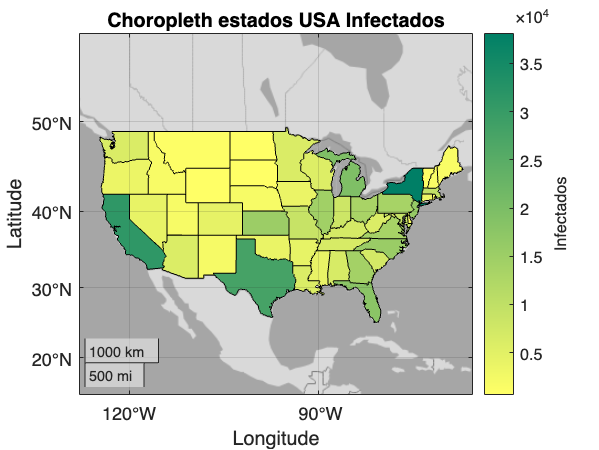

regresion.NumOrdenadoresInfectados = zeros(height(regresion), 1);

for i = 1:height(regresion)
    dentroDeLaRegion = zeroaccess(zeroaccess(:,1) >= regresion.minlatitude(i) & ...
                                   zeroaccess(:,1) <= regresion.maxlatitude(i) & ...
                                   zeroaccess(:,2) >= regresion.minlongitude(i) & ...

                                   zeroaccess(:,2) <= regresion.maxlongitude(i), :);
    OrdenadoresZero = size(dentroDeLaRegion, 1);
    regresion.NumOrdenadoresInfectados(i) = OrdenadoresZero;
end

Ahora sí, se procede con el modelo de regresión lineal.

modelo = fitlm(regresion, 'NumOrdenadoresInfectados ~ Casas_internet + Casas_ordenador + Gente_con_internet + Gente_ordenador + IXPs + Poblacion + ISPs + Inversion + ITU + land');
disp(modelo);

Han resultado significativas la población, los ISPs, la inversión y el área del país. De esta forma, países con mayor población tienden a tener menos infecciones por unidad de población, debido a su coeficiente negativo. Sin embargo, países con mayor área terrestre tienden a tener más infecciones, lo que puede significar que a mayor población, mayor es también la infraestructura de protección contra amenazas informáticas, pero también son más atacados. Además, se concluye que un mayor número de ISPs está asociado con un aumento en las infecciones, y que mayores inversiones en tecnología están asociadas con más infecciones, ambos posiblemente debidos a mayor conectividad. 

Factores como el porcentaje de hogares y personas con acceso a Internet y ordenadores no mostraron una relación significativa con el número de infecciones, lo que sugiere que no son los determinantes más fuertes en este contexto.

El R-cuadrado de 0.632 indica que el 63.2% de la variabilidad en el número de ordenadores infectados es explicada por el modelo. Y un p-valor bajo muestra que el modelo es adecuado.

# 8. APRENDIENDO

Vamos a estudiar distintos ataques, sus efectos, de qué tipo son o en qué zonas se produjeron. Para ello leemos todos los json y cremos una tabla con toda la información (datastore).

expectedFields = {'action', 'actor', 'asset', 'attribute', 'discovery_method', 'impact', 'incident_id', 'notes', 'plus', 'reference', 'schema_version', 'security_incident', 'source_id', 'summary', 'timeline', 'victim'};
fds = fileDatastore('data/vcdb', 'ReadFcn', @(x) readjson(x, expectedFields))
T=[];
while hasdata(fds)
      T = [T; read(fds)];
end
T

### 8.1 SELECCIÓN DE DATOS

Seleccionamos ataques de nuestra zona (EEUU, Canadá).

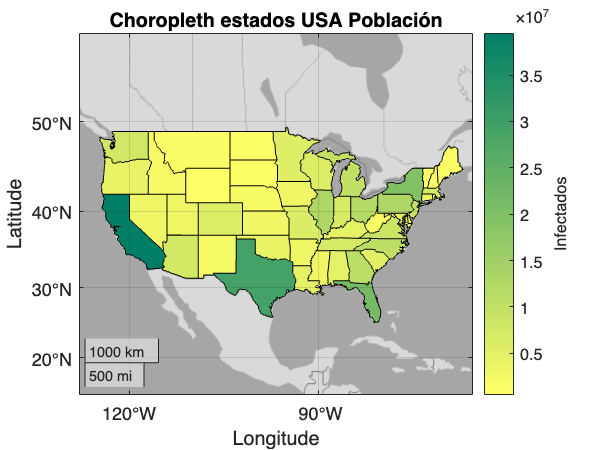

T2 = selectIANACountries(T, 'US');

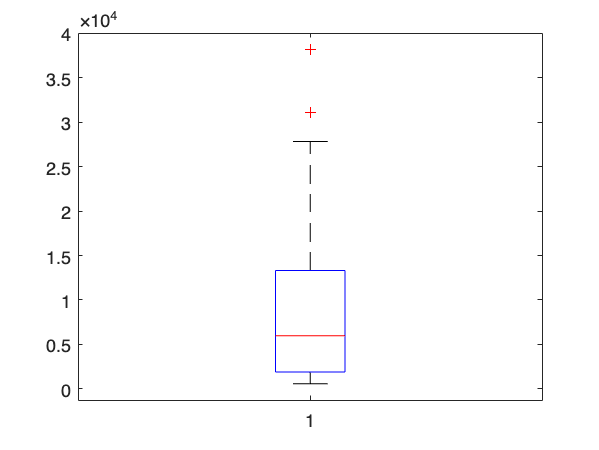

T3 = selectIANACountries(T, 'CA');

TT=vertcat(T2,T3);

### 8.2 VISUALIZANDO

#### 8.2.1 ATAQUES

action=countAction(TT, 'action');
bar(categorical(action.OriginalVariableNames),action.Var1)
title('Tipos de ataques')

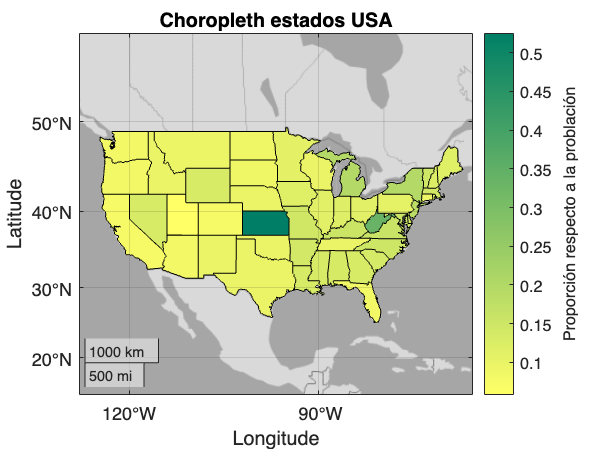

hack=countActionHackingVariety(TT, 'action', 'hacking', 'variety');
bar(categorical(hack.OriginalVariableNames),hack.Var1)
title('Tipos de Hackeos')
physical=countActionHackingVariety(TT, 'action', 'physical', 'variety');
bar(categorical(physical.OriginalVariableNames),physical.Var1)
title('Tipos de Ataques Físicos')
misuse=countActionHackingVariety(TT, 'action', 'misuse', 'variety');
bar(categorical(misuse.OriginalVariableNames),misuse.Var1)
title('Tipos de Abuso / Maluso')

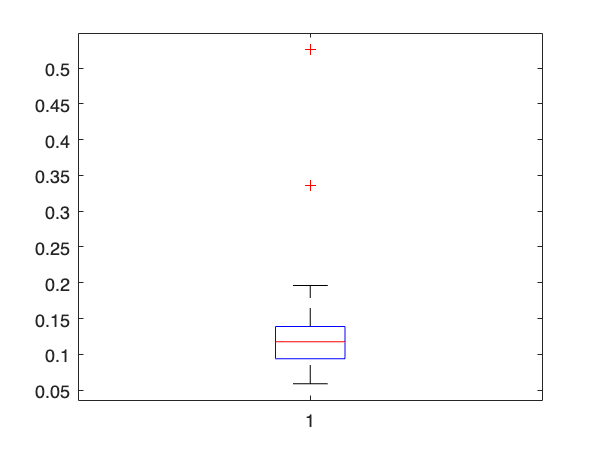

malware=countActionHackingVariety(TT, 'action', 'malware', 'variety');
bar(categorical(malware.OriginalVariableNames),malware.Var1)
title('Tipos de Malwares')

error=countActionHackingVariety(TT, 'action', 'error', 'variety');
bar(categorical(error.OriginalVariableNames),error.Var1)
title('Tipos de Errores')
social=countActionHackingVariety(TT, 'action', 'social', 'variety');
bar(categorical(social.OriginalVariableNames),social.Var1)
title('Tipos de Ataques Sociales')

#### 8.2.2 ATACANTES / VÍCTIMAS.

actor=countAction(TT, 'actor');
bar(categorical(actor.OriginalVariableNames),actor.Var1)
title('Tipos de Atacantes')

external=countActionHackingVariety(TT, 'actor', 'external', 'variety');
bar(categorical(external.OriginalVariableNames),external.Var1)

fds =   FileDatastore with properties:

                       Files: {
                              ' .../DRIVE/PROYECTO/data/vcdb/0012CC25-9167-40D8-8FE3-3D0DFD8FB6BB.json';
                              ' .../DRIVE/PROYECTO/data/vcdb/002599D4-A872-433B-9980-BD9F257B283F.json';
                              ' .../DRIVE/PROYECTO/data/vcdb/005C42A3-3FE8-47B5-866B-AFBB5E3F5B95.json'
                               ... and 1640 more
                              }
                     Folders: {
                              '/Users/annagilmoliner/CD 2023:2024/SDA/DRIVE/PROYECTO/data/vcdb'
                              }
                 UniformRead: 0
                    ReadMode: 'file'
                   BlockSize: Inf
                  PreviewFcn: @(x)readjson(x,expectedFields)
      SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    

title('Atacantes Externos')

internal=countActionHackingVariety(TT, 'actor', 'internal', 'variety');
bar(categorical(internal.OriginalVariableNames),internal.Var1)
title('Atacantes Internos')

T = 1643×1 struct array with fields:
    action
    actor
    asset
    attribute
    discovery_method
    impact
    incident_id
    notes
    plus
    reference
    schema_version
    security_incident
    source_id
    summary
    timeline
    victim


victimas=countVictims(TT, 'victim', 'victim_id');

vic=victimas(victimas.Var1>3,:);%experian 7 pfizer 5 las que mas tienen
bar(categorical(vic.OriginalVariableNames),vic.Var1)
title('Víctimas')

#### 8.2.3 ESTADOS UNIDOS Y CANADÁ.

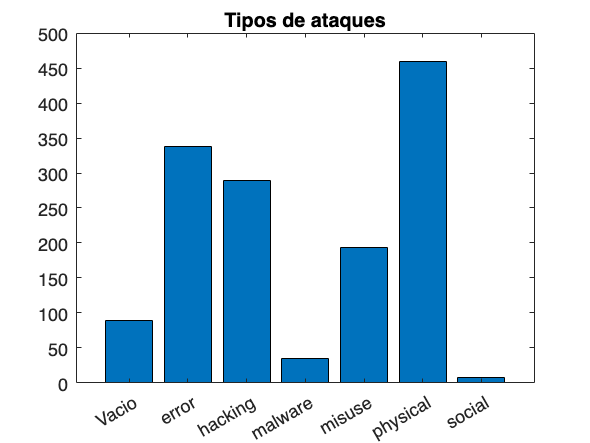

ataquesCA=countAction(T2, 'action');
bar(categorical(ataquesCA.OriginalVariableNames),ataquesCA.Var1)
title('Tipos de Ataques a Estados Unidos')

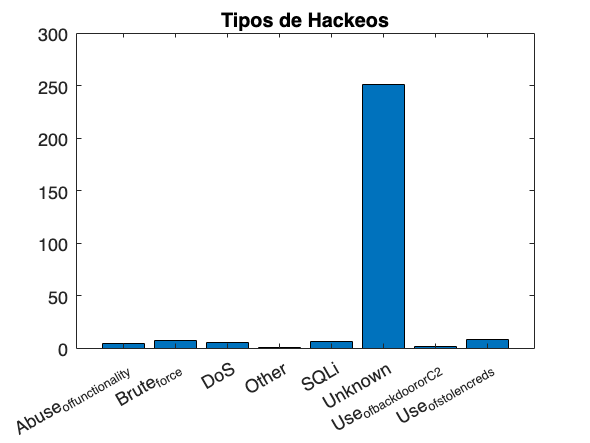


ataquesUS=countAction(T3, 'action');
bar(categorical(ataquesUS.OriginalVariableNames),ataquesUS.Var1)
title('Tipos de Ataques a Canada')

### 8.3 ESTUDIO POR ESTADOS (Choropleth)

Realizamos un análisis con mayor detalle, usando información sobre los estados de EEUU realizaremos un choroplet de los ataques por estas regiones.

estados = countVictims(T2, 'victim', 'state');
estados.OriginalVariableNames=arrayfun(@upper,estados.OriginalVariableNames);

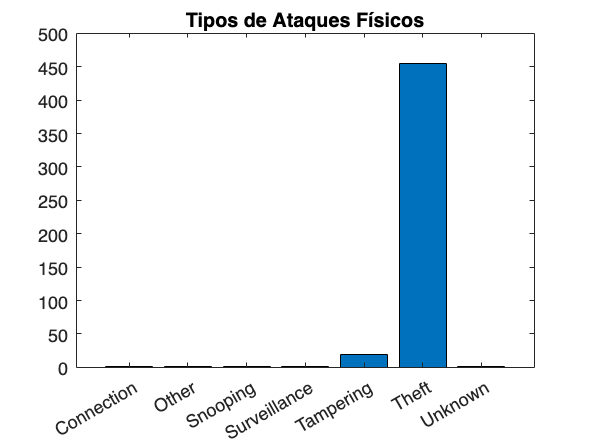

keys = estados.OriginalVariableNames;

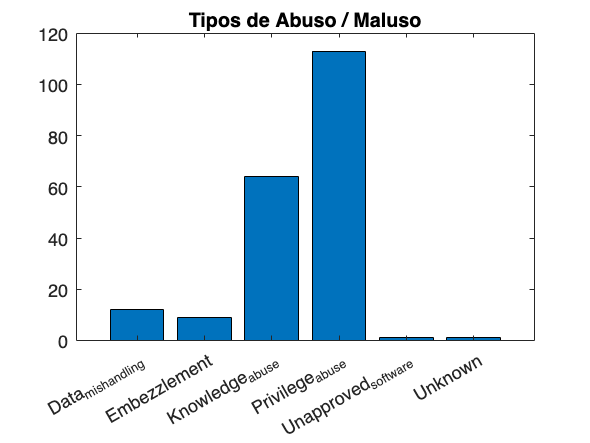

values = estados.Var1;

[uniqueKeys, ~, idx] = unique(keys);

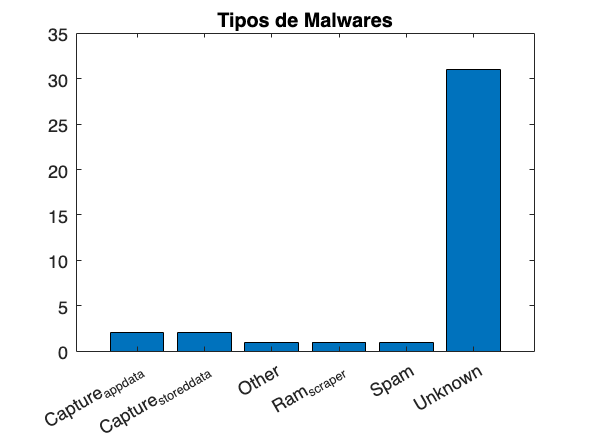


summedValues = accumarray(idx, values);


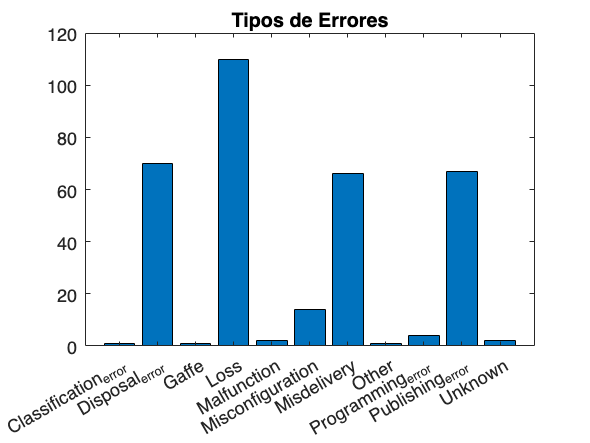

resultTable = table(uniqueKeys, summedValues, 'VariableNames', {'Estados', 'Ataques'});
ejem= fileread("state_boundaries.json");
data=jsondecode(ejem);

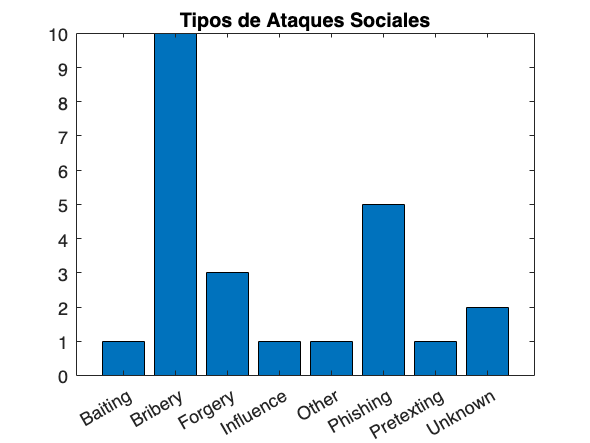

%coordenadas=struct2table(data)
colnames = {'ISO3166A2','nombre','minlatitude','maxlatitude','minlongitude','maxlongitude'};
t_estados = table(cell(0,1), cell(0,1),zeros(0,1), zeros(0,1), zeros(0,1), zeros(0,1), 'VariableNames', colnames);

stateCodes = {'AL', 'AK', 'AZ', 'AR', 'CA', 'CO', 'CT', 'DE', 'FL', 'GA','HI', 'ID', 'IL', 'IN', 'IA', 'KS', 'KY', 'LA', 'ME', 'MD', 'MA', 'MI', 'MN', 'MS', 'MO', 'MT', 'NE', 'NV', 'NH', 'NJ', 'NM', 'NY', 'NC', 'ND', 'OH', 'OK', 'OR', 'PA', 'RI', 'SC', 'SD', 'TN', 'TX', 'UT', 'VT', 'VA', 'WA', 'WV', 'WI', 'WY'};
for i=1:length(stateCodes)
    nom=stateCodes{i};
    newrow={nom,data.(nom).name,data.(nom).min_lat,data.(nom).max_lat,data.(nom).min_lng,data.(nom).max_lng};
    t_estados=[t_estados;newrow];
end
t_estados;

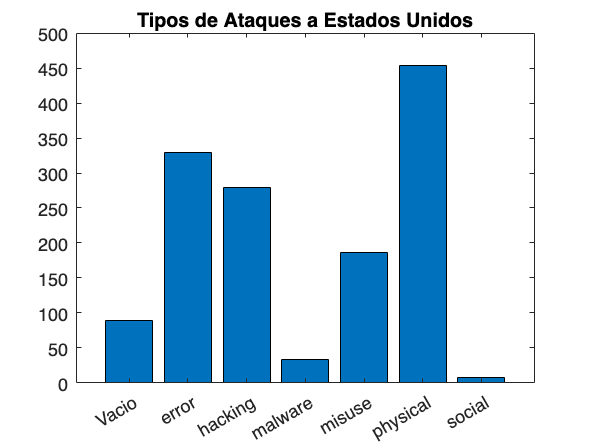

datos = innerjoin(resultTable,t_estados,'LeftKeys','Estados','RightKeys','ISO3166A2');
states = readgeotable("usastatelo.shp");
s = innerjoin(states,datos,"LeftKey","Name","RightKey","nombre");

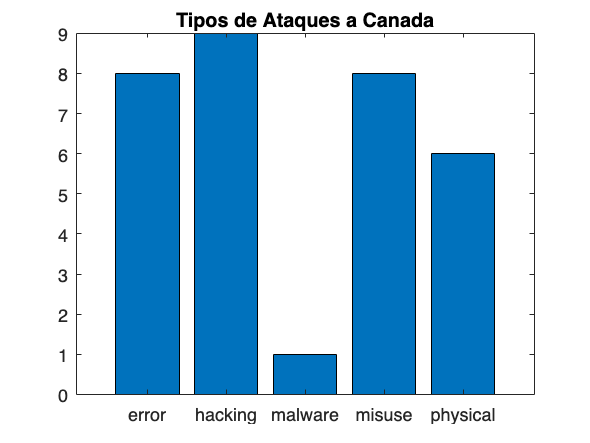


figure
rows = s.Name ~= "Hawaii" & s.Name ~= "Alaska";
statess = s(rows,:);

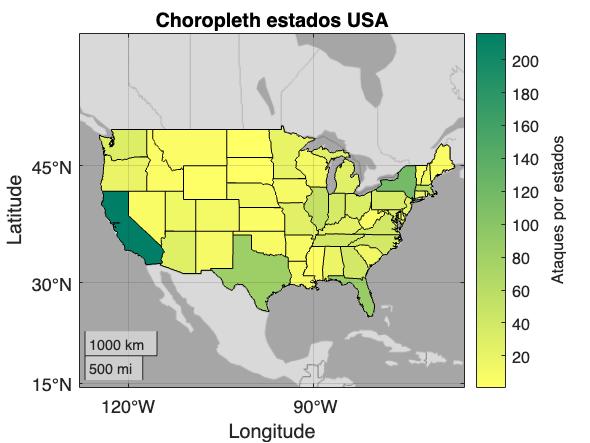

geoplot(statess,ColorVariable="Ataques");

geobasemap darkwater
title("Choropleth estados USA")
cb = colorbar;
cb.Label.String = "Ataques por estados";

cmap = flip(summer);
colormap(cmap)

geolimits([20.0 55.0],[-128.0 -65.5])

### 8.5 CONCLUSIONES

Centrándonos únicamente con los ataques que se dan en nuestra zona (EEUU, Canadá), podemos observar que los ataques producidos son muy diversos, sin embargo,  destacamos los ataques físicos, por error o por hackeo. Vemos que la mayoría de ataques físicos se producen con intención de robo, también destacamos que en la mayoría de hackeos se desconoce por completo el tipo. Algo similar sucede con los ataques producidos con malwares. Los ataques por abuso o maluso suelen darse por un abuso de conocimiento o por abusos de privilegio. Otros tipos de ataques por errores vienen dados por pérdidas, entregas erróneas, publicaciones erróneas, errores de eliminación, etc.

A continuación veremos las posibles diferencias entre los tipos de ataques que se producen en EEUU y en Canadá. Por un lado, en EEUU (donde se producen una mayor cantidad de ataques), mayoritáriamente suelen ser ataques físicos, por error, hackeros o por un mal uso. En Canadá sucede algo muy sumilar, auque prevalecen los ataques por hackeos por encima de todos. También hay un gran número de ataques por error, por un mal uso y también por ataques físicos, sin embargo, es mucho menor el número de ataques con malware.

Por último observamos que los estados con un mayor número de víctimas producidos por ataques son California y Nueva York.

## 9. CONCLUSIONES FINALES

El análisis comparativo entre las IPs de 2013 y 2019 en la zona de ARIN revela un crecimiento exponencial en el número de IPs asociadas a "Malicious Host", sugiriendo un aumento en la actividad de ciberdelincuencia y posiblemente una mayor utilización de tecnologías vulnerables en esta región. 

Además, se observa una mayor concentración de infecciones en la costa este de los Estados Unidos, posiblemente debido a la densidad de población en esta área. Aunque, este número absoluto de infecciones es mayor en Estados Unidos que en Canadá, la proporción de la población infectada es más alta en Canadá lo que indica una situación relativa más grave en términos de la población en Canadá. 

Sumado a esto, se identifican correlaciones entre la densidad de población y la incidencia de infecciones, especialmente en estados densamente poblados como California y Nueva York. Sin embargo, estados con densidades más bajas como West Virginia y Kansas muestran valores anormalmente altos de infecciones, posiblemente debido a una menor conciencia sobre ciberseguridad y, por lo tanto, una mayor vulnerabilidad ante infecciones.